Progetto segnali (Vollero)

segnale101

Analisi del segnale nel tempo 

figure(1)
segnale = data.segnale

Unable to resolve the name data.segnale.

%fs = data.Fs
tempo = data.time

plot(tempo,segnale)
xlim([0 5])
xlabel('Tempo[s]')
ylabel('segnale')


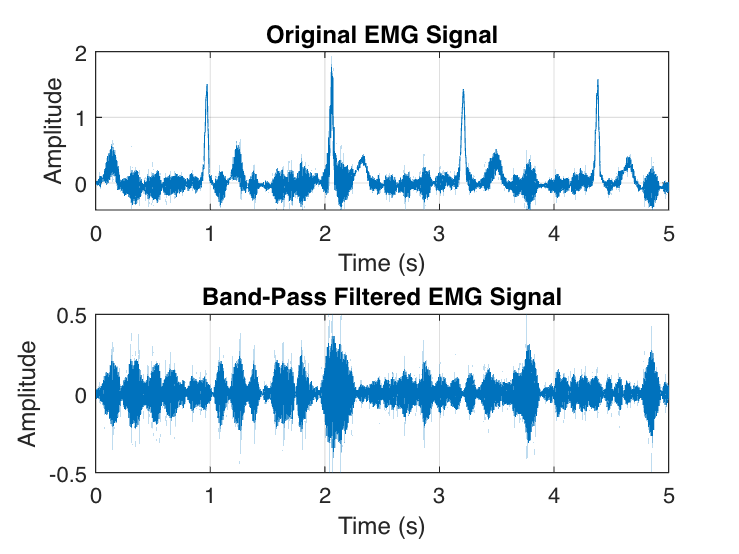

% band pass filter 
fs = 360;
emg_signal = segnale;
t = 0:0.001:1;
% Define filter parameters
low_freq = 80; % Low cutoff frequency in Hz
high_freq = 120; % High cutoff frequency in Hz
order = 4; % Filter order (you can adjust this)

% Design a band-pass Butterworth filter
[b, a] = butter(order, [low_freq, high_freq] / (fs/ 2));

% Apply the band-pass filter to the EMG signal
filtered_emg = filtfilt(b, a, emg_signal);

% Plot the original and filtered EMG signals
figure;
subplot(2,1,1);
plot(tempo, emg_signal);
xlim([0 5])
title('Original EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(tempo, filtered_emg);
xlim([0 5])
title('Band-Pass Filtered EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%fully wave rectification
% Sample EMG signal 


emg_signal = segnale;

% Full-wave rectification
rectified_emg = abs(emg_signal);

% Plot the original and rectified signals
figure;
subplot(2,1,1);
plot(tempo,emg_signal);
xlim([0 5])
title('Original EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(tempo, rectified_emg);
xlim([0 5])
title('Rectified EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

Analisi del comportamento in frequenza 

figure(2)
u1 = (0:length(segnale)-1)/length(segnale) 

u1 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


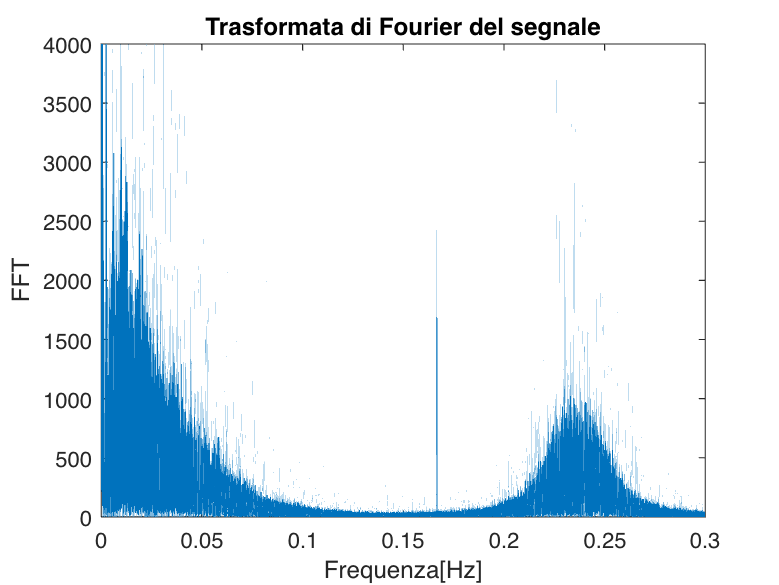

plot(u1,(abs(fft(segnale))))
xlim([0,0.3])
ylim([0 4000])
title('Trasformata di Fourier del segnale')
xlabel('Frequenza[Hz]')
ylabel('FFT')


%poiche l'andamento del segnale nel tempo e nella frequenza 
%è minore rispetto al rumore, è opportuno applicare un filtro fir

Filtro fir

M = 100 % M numero di vincoli di progettazione

M = 100

N = 100 % N numero di gradi di libertà 

N = 100

u = linspace(0,0.5,M)'; %vettore con freuqneze normalizzate in cui sono appliacti i vincoli definiti su H 
H = (u < 0.071) 

H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


u = repmat(u,1,N-1) %ripete u per una riga e N-1 colonne

u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0

n = 1:N-1

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


n = repmat(n,M,1)

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15   

C = [ones(M,1) 2*cos(2*pi*u.*n)] %ones:crea una matrice Mx1 di tutti 1

C =     1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112    1.1601    1.1078    1.0545    1.0000    0.9445    0.8881    0.8308    0.7727    0.7138    0.6541    0.5938    0.5329    0.4715    0.4096    0.3473    0.2846    0.2217    0.1585    0.0952    0

h = C\H

h =     0.1465
    0.1414
    0.1267
    0.1042
    0.0768
    0.0475
    0.0197
   -0.0036
   -0.0205
   -0.0299


h = [h(end:-1:2);h]

h =     0.0025
    0.0045
    0.0031
    0.0010
   -0.0013
   -0.0034
   -0.0047
   -0.0051
   -0.0044
   -0.0028


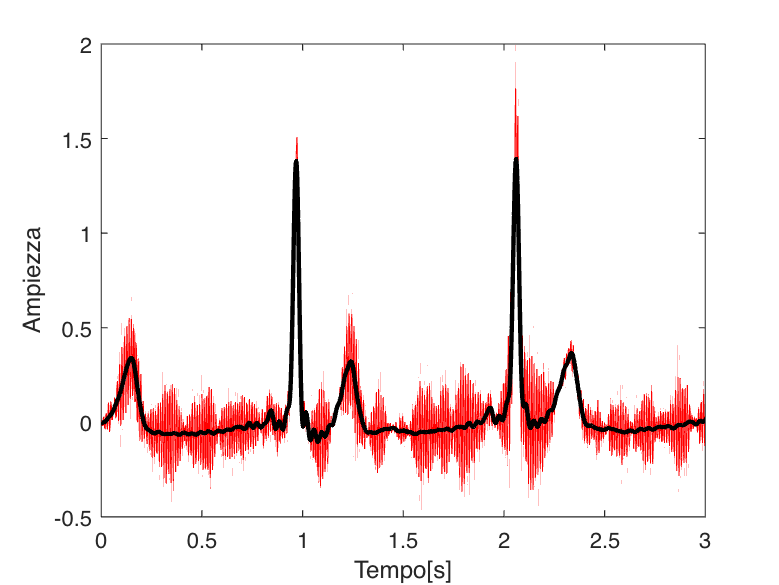


 

figure(4)
plot(tempo,segnale,'Color','r')
hold on
plot(tempo,conv(segnale,h,'same'),'k','LineWidth',2)
xlim([0 3])
xlabel('Tempo[s]')
ylabel('Ampiezza')
hold off 

Ottimizzazione rispetto alla frequenza di taglio (SNR)

f = [0.02:0.001:0.25]

f =     0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0630    0.0640    0.0650    0.0660    0.0670    0.0680    0.0690


frequenza = length(f)

frequenza = 231

SignalPower = @(x) norm(x(:)-mean(x(:)))^2/length(x(:)) 

SignalPower = function_handle with value:
    @(x)norm(x(:)-mean(x(:)))^2/length(x(:))


for i = 1:frequenza
    M = 100  %vincoli
    N = 100 %parametri liberi
    u = linspace(0,0.5,M)'
    H = (u < f(i))
    u = repmat(u,1,N-1)
    n = 1:N-1
    n = repmat(n,M,1)
    C = [ones(M,1) 2*cos(2*pi*u.*n)]
    h = C\H
    h = [h(end:-1:2);h]
    segfiltrato = conv(segnale,h,'same')
    segmento_segnale = segfiltrato((tempo>0.805)&(tempo<1.330))
    segmento_rumore = segfiltrato((tempo>1.330)&(tempo<1.891))
    SNR(i) = [10*log10(SignalPower(segmento_segnale)/SignalPower(segmento_rumore))]
    w(i) = f(i)
end

M = 100

N = 100

u =          0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0


u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15   

C =     1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112    1.1601    1.1078    1.0545    1.0000    0.9445    0.8881    0.8308    0.7727    0.7138    0.6541    0.5938    0.5329    0.4715    0.4096    0.3473    0.2846    0.2217    0.1585    0.0952    0

h =     0.0354
    0.0353
    0.0351
    0.0347
    0.0342
    0.0336
    0.0328
    0.0320
    0.0310
    0.0299


h =    -0.0025
   -0.0050
   -0.0049
   -0.0048
   -0.0046
   -0.0043
   -0.0040
   -0.0036
   -0.0032
   -0.0028


segfiltrato =    -0.0134
   -0.0141
   -0.0149
   -0.0160
   -0.0166
   -0.0160
   -0.0149
   -0.0141
   -0.0128
   -0.0101


segmento_segnale =     0.0154
    0.0049
   -0.0045
   -0.0137
   -0.0243
   -0.0358
   -0.0461
   -0.0551
   -0.0647
   -0.0748


segmento_rumore =    -0.0636
   -0.0694
   -0.0729
   -0.0755
   -0.0790
   -0.0822
   -0.0832
   -0.0832
   -0.0839
   -0.0846


SNR = 14.5261

w = 0.0200

M = 100

N = 100

u =          0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0


u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15   

C =     1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112    1.1601    1.1078    1.0545    1.0000    0.9445    0.8881    0.8308    0.7727    0.7138    0.6541    0.5938    0.5329    0.4715    0.4096    0.3473    0.2846    0.2217    0.1585    0.0952    0

h =     0.0455
    0.0453
    0.0448
    0.0441
    0.0431
    0.0417
    0.0402
    0.0383
    0.0363
    0.0341


h =     0.0025
    0.0050
    0.0048
    0.0046
    0.0043
    0.0038
    0.0033
    0.0027
    0.0021
    0.0014


segfiltrato =     0.0111
    0.0107
    0.0106
    0.0111
    0.0113
    0.0108
    0.0102
    0.0105
    0.0108
    0.0105


segmento_segnale =     0.0780
    0.0855
    0.0898
    0.0919
    0.0935
    0.0940
    0.0914
    0.0859
    0.0794
    0.0721


segmento_rumore =    -0.0722
   -0.0730
   -0.0746
   -0.0757
   -0.0745
   -0.0724
   -0.0712
   -0.0699
   -0.0670
   -0.0632


SNR =    14.5261   20.0452


w =     0.0200    0.0210


M = 100

N = 100

u =          0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0


u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15   

C =     1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112    1.1601    1.1078    1.0545    1.0000    0.9445    0.8881    0.8308    0.7727    0.7138    0.6541    0.5938    0.5329    0.4715    0.4096    0.3473    0.2846    0.2217    0.1585    0.0952    0

h =     0.0455
    0.0453
    0.0448
    0.0441
    0.0431
    0.0417
    0.0402
    0.0383
    0.0363
    0.0341


h =     0.0025
    0.0050
    0.0048
    0.0046
    0.0043
    0.0038
    0.0033
    0.0027
    0.0021
    0.0014


segfiltrato =     0.0111
    0.0107
    0.0106
    0.0111
    0.0113
    0.0108
    0.0102
    0.0105
    0.0108
    0.0105


segmento_segnale =     0.0780
    0.0855
    0.0898
    0.0919
    0.0935
    0.0940
    0.0914
    0.0859
    0.0794
    0.0721


segmento_rumore =    -0.0722
   -0.0730
   -0.0746
   -0.0757
   -0.0745
   -0.0724
   -0.0712
   -0.0699
   -0.0670
   -0.0632


SNR =    14.5261   20.0452   20.0452


w =     0.0200    0.0210    0.0220


M = 100

N = 100

u =          0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0455
    0.0453
    0.0448
    0.0441
    0.0431
    0.0417
    0.0402
    0.0383
    0.0363
    0.0341


h = 199×1
    0.0025
    0.0050
    0.0048
    0.0046
    0.0043
    0.0038
    0.0033
    0.0027
    0.0021
    0.0014


segfiltrato = 650000×1
    0.0111
    0.0107
    0.0106
    0.0111
    0.0113
    0.0108
    0.0102
    0.0105
    0.0108
    0.0105


segmento_segnale = 189×1
    0.0780
    0.0855
    0.0898
    0.0919
    0.0935
    0.0940
    0.0914
    0.0859
    0.0794
    0.0721


segmento_rumore = 202×1
   -0.0722
   -0.0730
   -0.0746
   -0.0757
   -0.0745
   -0.0724
   -0.0712
   -0.0699
   -0.0670
   -0.0632


SNR = 1×4
   14.5261   20.0452   20.0452   20.0452


w = 1×4
    0.0200    0.0210    0.0220    0.0230


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0455
    0.0453
    0.0448
    0.0441
    0.0431
    0.0417
    0.0402
    0.0383
    0.0363
    0.0341


h = 199×1
    0.0025
    0.0050
    0.0048
    0.0046
    0.0043
    0.0038
    0.0033
    0.0027
    0.0021
    0.0014


segfiltrato = 650000×1
    0.0111
    0.0107
    0.0106
    0.0111
    0.0113
    0.0108
    0.0102
    0.0105
    0.0108
    0.0105


segmento_segnale = 189×1
    0.0780
    0.0855
    0.0898
    0.0919
    0.0935
    0.0940
    0.0914
    0.0859
    0.0794
    0.0721


segmento_rumore = 202×1
   -0.0722
   -0.0730
   -0.0746
   -0.0757
   -0.0745
   -0.0724
   -0.0712
   -0.0699
   -0.0670
   -0.0632


SNR = 1×5
   14.5261   20.0452   20.0452   20.0452   20.0452


w = 1×5
    0.0200    0.0210    0.0220    0.0230    0.0240


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0455
    0.0453
    0.0448
    0.0441
    0.0431
    0.0417
    0.0402
    0.0383
    0.0363
    0.0341


h = 199×1
    0.0025
    0.0050
    0.0048
    0.0046
    0.0043
    0.0038
    0.0033
    0.0027
    0.0021
    0.0014


segfiltrato = 650000×1
    0.0111
    0.0107
    0.0106
    0.0111
    0.0113
    0.0108
    0.0102
    0.0105
    0.0108
    0.0105


segmento_segnale = 189×1
    0.0780
    0.0855
    0.0898
    0.0919
    0.0935
    0.0940
    0.0914
    0.0859
    0.0794
    0.0721


segmento_rumore = 202×1
   -0.0722
   -0.0730
   -0.0746
   -0.0757
   -0.0745
   -0.0724
   -0.0712
   -0.0699
   -0.0670
   -0.0632


SNR = 1×6
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452


w = 1×6
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0556
    0.0553
    0.0544
    0.0531
    0.0512
    0.0488
    0.0460
    0.0428
    0.0393
    0.0355


h = 199×1
   -0.0025
   -0.0050
   -0.0047
   -0.0044
   -0.0039
   -0.0033
   -0.0025
   -0.0017
   -0.0009
   -0.0000


segfiltrato = 650000×1
   -0.0012
    0.0011
    0.0032
    0.0047
    0.0065
    0.0091
    0.0119
    0.0139
    0.0159
    0.0187


segmento_segnale = 189×1
   -0.0443
   -0.0324
   -0.0177
   -0.0015
    0.0137
    0.0283
    0.0437
    0.0592
    0.0727
    0.0834


segmento_rumore = 202×1
   -0.0648
   -0.0653
   -0.0637
   -0.0614
   -0.0603
   -0.0593
   -0.0567
   -0.0536
   -0.0519
   -0.0507


SNR = 1×7
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044


w = 1×7
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0556
    0.0553
    0.0544
    0.0531
    0.0512
    0.0488
    0.0460
    0.0428
    0.0393
    0.0355


h = 199×1
   -0.0025
   -0.0050
   -0.0047
   -0.0044
   -0.0039
   -0.0033
   -0.0025
   -0.0017
   -0.0009
   -0.0000


segfiltrato = 650000×1
   -0.0012
    0.0011
    0.0032
    0.0047
    0.0065
    0.0091
    0.0119
    0.0139
    0.0159
    0.0187


segmento_segnale = 189×1
   -0.0443
   -0.0324
   -0.0177
   -0.0015
    0.0137
    0.0283
    0.0437
    0.0592
    0.0727
    0.0834


segmento_rumore = 202×1
   -0.0648
   -0.0653
   -0.0637
   -0.0614
   -0.0603
   -0.0593
   -0.0567
   -0.0536
   -0.0519
   -0.0507


SNR = 1×8
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044


w = 1×8
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0556
    0.0553
    0.0544
    0.0531
    0.0512
    0.0488
    0.0460
    0.0428
    0.0393
    0.0355


h = 199×1
   -0.0025
   -0.0050
   -0.0047
   -0.0044
   -0.0039
   -0.0033
   -0.0025
   -0.0017
   -0.0009
   -0.0000


segfiltrato = 650000×1
   -0.0012
    0.0011
    0.0032
    0.0047
    0.0065
    0.0091
    0.0119
    0.0139
    0.0159
    0.0187


segmento_segnale = 189×1
   -0.0443
   -0.0324
   -0.0177
   -0.0015
    0.0137
    0.0283
    0.0437
    0.0592
    0.0727
    0.0834


segmento_rumore = 202×1
   -0.0648
   -0.0653
   -0.0637
   -0.0614
   -0.0603
   -0.0593
   -0.0567
   -0.0536
   -0.0519
   -0.0507


SNR = 1×9
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044


w = 1×9
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0556
    0.0553
    0.0544
    0.0531
    0.0512
    0.0488
    0.0460
    0.0428
    0.0393
    0.0355


h = 199×1
   -0.0025
   -0.0050
   -0.0047
   -0.0044
   -0.0039
   -0.0033
   -0.0025
   -0.0017
   -0.0009
   -0.0000


segfiltrato = 650000×1
   -0.0012
    0.0011
    0.0032
    0.0047
    0.0065
    0.0091
    0.0119
    0.0139
    0.0159
    0.0187


segmento_segnale = 189×1
   -0.0443
   -0.0324
   -0.0177
   -0.0015
    0.0137
    0.0283
    0.0437
    0.0592
    0.0727
    0.0834


segmento_rumore = 202×1
   -0.0648
   -0.0653
   -0.0637
   -0.0614
   -0.0603
   -0.0593
   -0.0567
   -0.0536
   -0.0519
   -0.0507


SNR = 1×10
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044


w = 1×10
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0556
    0.0553
    0.0544
    0.0531
    0.0512
    0.0488
    0.0460
    0.0428
    0.0393
    0.0355


h = 199×1
   -0.0025
   -0.0050
   -0.0047
   -0.0044
   -0.0039
   -0.0033
   -0.0025
   -0.0017
   -0.0009
   -0.0000


segfiltrato = 650000×1
   -0.0012
    0.0011
    0.0032
    0.0047
    0.0065
    0.0091
    0.0119
    0.0139
    0.0159
    0.0187


segmento_segnale = 189×1
   -0.0443
   -0.0324
   -0.0177
   -0.0015
    0.0137
    0.0283
    0.0437
    0.0592
    0.0727
    0.0834


segmento_rumore = 202×1
   -0.0648
   -0.0653
   -0.0637
   -0.0614
   -0.0603
   -0.0593
   -0.0567
   -0.0536
   -0.0519
   -0.0507


SNR = 1×11
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044


w = 1×11
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0657
    0.0652
    0.0638
    0.0616
    0.0585
    0.0547
    0.0502
    0.0452
    0.0398
    0.0341


h = 199×1
    0.0025
    0.0049
    0.0046
    0.0041
    0.0034
    0.0026
    0.0017
    0.0006
   -0.0004
   -0.0014


segfiltrato = 650000×1
   -0.0047
   -0.0050
   -0.0045
   -0.0030
   -0.0013
    0.0001
    0.0018
    0.0046
    0.0078
    0.0105


segmento_segnale = 189×1
   -0.0410
   -0.0463
   -0.0515
   -0.0549
   -0.0546
   -0.0509
   -0.0457
   -0.0391
   -0.0292
   -0.0162


segmento_rumore = 202×1
   -0.0542
   -0.0530
   -0.0533
   -0.0537
   -0.0525
   -0.0510
   -0.0511
   -0.0516
   -0.0510
   -0.0499


SNR = 1×12
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417


w = 1×12
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0657
    0.0652
    0.0638
    0.0616
    0.0585
    0.0547
    0.0502
    0.0452
    0.0398
    0.0341


h = 199×1
    0.0025
    0.0049
    0.0046
    0.0041
    0.0034
    0.0026
    0.0017
    0.0006
   -0.0004
   -0.0014


segfiltrato = 650000×1
   -0.0047
   -0.0050
   -0.0045
   -0.0030
   -0.0013
    0.0001
    0.0018
    0.0046
    0.0078
    0.0105


segmento_segnale = 189×1
   -0.0410
   -0.0463
   -0.0515
   -0.0549
   -0.0546
   -0.0509
   -0.0457
   -0.0391
   -0.0292
   -0.0162


segmento_rumore = 202×1
   -0.0542
   -0.0530
   -0.0533
   -0.0537
   -0.0525
   -0.0510
   -0.0511
   -0.0516
   -0.0510
   -0.0499


SNR = 1×13
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417


w = 1×13
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0657
    0.0652
    0.0638
    0.0616
    0.0585
    0.0547
    0.0502
    0.0452
    0.0398
    0.0341


h = 199×1
    0.0025
    0.0049
    0.0046
    0.0041
    0.0034
    0.0026
    0.0017
    0.0006
   -0.0004
   -0.0014


segfiltrato = 650000×1
   -0.0047
   -0.0050
   -0.0045
   -0.0030
   -0.0013
    0.0001
    0.0018
    0.0046
    0.0078
    0.0105


segmento_segnale = 189×1
   -0.0410
   -0.0463
   -0.0515
   -0.0549
   -0.0546
   -0.0509
   -0.0457
   -0.0391
   -0.0292
   -0.0162


segmento_rumore = 202×1
   -0.0542
   -0.0530
   -0.0533
   -0.0537
   -0.0525
   -0.0510
   -0.0511
   -0.0516
   -0.0510
   -0.0499


SNR = 1×14
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417


w = 1×14
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0657
    0.0652
    0.0638
    0.0616
    0.0585
    0.0547
    0.0502
    0.0452
    0.0398
    0.0341


h = 199×1
    0.0025
    0.0049
    0.0046
    0.0041
    0.0034
    0.0026
    0.0017
    0.0006
   -0.0004
   -0.0014


segfiltrato = 650000×1
   -0.0047
   -0.0050
   -0.0045
   -0.0030
   -0.0013
    0.0001
    0.0018
    0.0046
    0.0078
    0.0105


segmento_segnale = 189×1
   -0.0410
   -0.0463
   -0.0515
   -0.0549
   -0.0546
   -0.0509
   -0.0457
   -0.0391
   -0.0292
   -0.0162


segmento_rumore = 202×1
   -0.0542
   -0.0530
   -0.0533
   -0.0537
   -0.0525
   -0.0510
   -0.0511
   -0.0516
   -0.0510
   -0.0499


SNR = 1×15
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417


w = 1×15
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0657
    0.0652
    0.0638
    0.0616
    0.0585
    0.0547
    0.0502
    0.0452
    0.0398
    0.0341


h = 199×1
    0.0025
    0.0049
    0.0046
    0.0041
    0.0034
    0.0026
    0.0017
    0.0006
   -0.0004
   -0.0014


segfiltrato = 650000×1
   -0.0047
   -0.0050
   -0.0045
   -0.0030
   -0.0013
    0.0001
    0.0018
    0.0046
    0.0078
    0.0105


segmento_segnale = 189×1
   -0.0410
   -0.0463
   -0.0515
   -0.0549
   -0.0546
   -0.0509
   -0.0457
   -0.0391
   -0.0292
   -0.0162


segmento_rumore = 202×1
   -0.0542
   -0.0530
   -0.0533
   -0.0537
   -0.0525
   -0.0510
   -0.0511
   -0.0516
   -0.0510
   -0.0499


SNR = 1×16
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417


w = 1×16
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0758
    0.0750
    0.0729
    0.0695
    0.0649
    0.0592
    0.0526
    0.0454
    0.0377
    0.0299


h = 199×1
   -0.0025
   -0.0049
   -0.0045
   -0.0038
   -0.0029
   -0.0019
   -0.0007
    0.0005
    0.0017
    0.0028


segfiltrato = 650000×1
   -0.0002
    0.0002
    0.0002
   -0.0002
   -0.0002
    0.0009
    0.0023
    0.0034
    0.0048
    0.0076


segmento_segnale = 189×1
    0.0401
    0.0386
    0.0363
    0.0323
    0.0251
    0.0157
    0.0067
   -0.0015
   -0.0101
   -0.0186


segmento_rumore = 202×1
   -0.0522
   -0.0534
   -0.0529
   -0.0521
   -0.0529
   -0.0541
   -0.0538
   -0.0531
   -0.0537
   -0.0548


SNR = 1×17
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986


w = 1×17
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0758
    0.0750
    0.0729
    0.0695
    0.0649
    0.0592
    0.0526
    0.0454
    0.0377
    0.0299


h = 199×1
   -0.0025
   -0.0049
   -0.0045
   -0.0038
   -0.0029
   -0.0019
   -0.0007
    0.0005
    0.0017
    0.0028


segfiltrato = 650000×1
   -0.0002
    0.0002
    0.0002
   -0.0002
   -0.0002
    0.0009
    0.0023
    0.0034
    0.0048
    0.0076


segmento_segnale = 189×1
    0.0401
    0.0386
    0.0363
    0.0323
    0.0251
    0.0157
    0.0067
   -0.0015
   -0.0101
   -0.0186


segmento_rumore = 202×1
   -0.0522
   -0.0534
   -0.0529
   -0.0521
   -0.0529
   -0.0541
   -0.0538
   -0.0531
   -0.0537
   -0.0548


SNR = 1×18
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986


w = 1×18
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0758
    0.0750
    0.0729
    0.0695
    0.0649
    0.0592
    0.0526
    0.0454
    0.0377
    0.0299


h = 199×1
   -0.0025
   -0.0049
   -0.0045
   -0.0038
   -0.0029
   -0.0019
   -0.0007
    0.0005
    0.0017
    0.0028


segfiltrato = 650000×1
   -0.0002
    0.0002
    0.0002
   -0.0002
   -0.0002
    0.0009
    0.0023
    0.0034
    0.0048
    0.0076


segmento_segnale = 189×1
    0.0401
    0.0386
    0.0363
    0.0323
    0.0251
    0.0157
    0.0067
   -0.0015
   -0.0101
   -0.0186


segmento_rumore = 202×1
   -0.0522
   -0.0534
   -0.0529
   -0.0521
   -0.0529
   -0.0541
   -0.0538
   -0.0531
   -0.0537
   -0.0548


SNR = 1×19
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986


w = 1×19
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0758
    0.0750
    0.0729
    0.0695
    0.0649
    0.0592
    0.0526
    0.0454
    0.0377
    0.0299


h = 199×1
   -0.0025
   -0.0049
   -0.0045
   -0.0038
   -0.0029
   -0.0019
   -0.0007
    0.0005
    0.0017
    0.0028


segfiltrato = 650000×1
   -0.0002
    0.0002
    0.0002
   -0.0002
   -0.0002
    0.0009
    0.0023
    0.0034
    0.0048
    0.0076


segmento_segnale = 189×1
    0.0401
    0.0386
    0.0363
    0.0323
    0.0251
    0.0157
    0.0067
   -0.0015
   -0.0101
   -0.0186


segmento_rumore = 202×1
   -0.0522
   -0.0534
   -0.0529
   -0.0521
   -0.0529
   -0.0541
   -0.0538
   -0.0531
   -0.0537
   -0.0548


SNR = 1×20
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986


w = 1×20
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0758
    0.0750
    0.0729
    0.0695
    0.0649
    0.0592
    0.0526
    0.0454
    0.0377
    0.0299


h = 199×1
   -0.0025
   -0.0049
   -0.0045
   -0.0038
   -0.0029
   -0.0019
   -0.0007
    0.0005
    0.0017
    0.0028


segfiltrato = 650000×1
   -0.0002
    0.0002
    0.0002
   -0.0002
   -0.0002
    0.0009
    0.0023
    0.0034
    0.0048
    0.0076


segmento_segnale = 189×1
    0.0401
    0.0386
    0.0363
    0.0323
    0.0251
    0.0157
    0.0067
   -0.0015
   -0.0101
   -0.0186


segmento_rumore = 202×1
   -0.0522
   -0.0534
   -0.0529
   -0.0521
   -0.0529
   -0.0541
   -0.0538
   -0.0531
   -0.0537
   -0.0548


SNR = 1×21
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986


w = 1×21
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0859
    0.0848
    0.0818
    0.0768
    0.0702
    0.0622
    0.0531
    0.0433
    0.0332
    0.0232


h = 199×1
    0.0025
    0.0049
    0.0043
    0.0035
    0.0024
    0.0011
   -0.0002
   -0.0016
   -0.0028
   -0.0039


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0014
    0.0027
    0.0034
    0.0042
    0.0061
    0.0081
    0.0096


segmento_segnale = 189×1
   -0.0119
    0.0059
    0.0218
    0.0361
    0.0496
    0.0610
    0.0676
    0.0693
    0.0679
    0.0635


segmento_rumore = 202×1
   -0.0527
   -0.0534
   -0.0554
   -0.0574
   -0.0576
   -0.0572
   -0.0579
   -0.0588
   -0.0580
   -0.0563


SNR = 1×22
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280


w = 1×22
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0859
    0.0848
    0.0818
    0.0768
    0.0702
    0.0622
    0.0531
    0.0433
    0.0332
    0.0232


h = 199×1
    0.0025
    0.0049
    0.0043
    0.0035
    0.0024
    0.0011
   -0.0002
   -0.0016
   -0.0028
   -0.0039


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0014
    0.0027
    0.0034
    0.0042
    0.0061
    0.0081
    0.0096


segmento_segnale = 189×1
   -0.0119
    0.0059
    0.0218
    0.0361
    0.0496
    0.0610
    0.0676
    0.0693
    0.0679
    0.0635


segmento_rumore = 202×1
   -0.0527
   -0.0534
   -0.0554
   -0.0574
   -0.0576
   -0.0572
   -0.0579
   -0.0588
   -0.0580
   -0.0563


SNR = 1×23
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280


w = 1×23
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0859
    0.0848
    0.0818
    0.0768
    0.0702
    0.0622
    0.0531
    0.0433
    0.0332
    0.0232


h = 199×1
    0.0025
    0.0049
    0.0043
    0.0035
    0.0024
    0.0011
   -0.0002
   -0.0016
   -0.0028
   -0.0039


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0014
    0.0027
    0.0034
    0.0042
    0.0061
    0.0081
    0.0096


segmento_segnale = 189×1
   -0.0119
    0.0059
    0.0218
    0.0361
    0.0496
    0.0610
    0.0676
    0.0693
    0.0679
    0.0635


segmento_rumore = 202×1
   -0.0527
   -0.0534
   -0.0554
   -0.0574
   -0.0576
   -0.0572
   -0.0579
   -0.0588
   -0.0580
   -0.0563


SNR = 1×24
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280


w = 1×24
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0859
    0.0848
    0.0818
    0.0768
    0.0702
    0.0622
    0.0531
    0.0433
    0.0332
    0.0232


h = 199×1
    0.0025
    0.0049
    0.0043
    0.0035
    0.0024
    0.0011
   -0.0002
   -0.0016
   -0.0028
   -0.0039


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0014
    0.0027
    0.0034
    0.0042
    0.0061
    0.0081
    0.0096


segmento_segnale = 189×1
   -0.0119
    0.0059
    0.0218
    0.0361
    0.0496
    0.0610
    0.0676
    0.0693
    0.0679
    0.0635


segmento_rumore = 202×1
   -0.0527
   -0.0534
   -0.0554
   -0.0574
   -0.0576
   -0.0572
   -0.0579
   -0.0588
   -0.0580
   -0.0563


SNR = 1×25
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280


w = 1×25
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0859
    0.0848
    0.0818
    0.0768
    0.0702
    0.0622
    0.0531
    0.0433
    0.0332
    0.0232


h = 199×1
    0.0025
    0.0049
    0.0043
    0.0035
    0.0024
    0.0011
   -0.0002
   -0.0016
   -0.0028
   -0.0039


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0014
    0.0027
    0.0034
    0.0042
    0.0061
    0.0081
    0.0096


segmento_segnale = 189×1
   -0.0119
    0.0059
    0.0218
    0.0361
    0.0496
    0.0610
    0.0676
    0.0693
    0.0679
    0.0635


segmento_rumore = 202×1
   -0.0527
   -0.0534
   -0.0554
   -0.0574
   -0.0576
   -0.0572
   -0.0579
   -0.0588
   -0.0580
   -0.0563


SNR = 1×26
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280


w = 1×26
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0960
    0.0945
    0.0903
    0.0834
    0.0744
    0.0636
    0.0516
    0.0391
    0.0266
    0.0147


h = 199×1
   -0.0025
   -0.0048
   -0.0042
   -0.0031
   -0.0018
   -0.0003
    0.0012
    0.0026
    0.0038
    0.0046


segfiltrato = 650000×1
   -0.0023
   -0.0015
   -0.0010
   -0.0008
   -0.0002
    0.0016
    0.0038
    0.0054
    0.0073
    0.0104


segmento_segnale = 189×1
   -0.0545
   -0.0529
   -0.0453
   -0.0329
   -0.0185
   -0.0023
    0.0165
    0.0364
    0.0541
    0.0678


segmento_rumore = 202×1
   -0.0549
   -0.0570
   -0.0572
   -0.0568
   -0.0576
   -0.0586
   -0.0577
   -0.0562
   -0.0558
   -0.0559


SNR = 1×27
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417


w = 1×27
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0960
    0.0945
    0.0903
    0.0834
    0.0744
    0.0636
    0.0516
    0.0391
    0.0266
    0.0147


h = 199×1
   -0.0025
   -0.0048
   -0.0042
   -0.0031
   -0.0018
   -0.0003
    0.0012
    0.0026
    0.0038
    0.0046


segfiltrato = 650000×1
   -0.0023
   -0.0015
   -0.0010
   -0.0008
   -0.0002
    0.0016
    0.0038
    0.0054
    0.0073
    0.0104


segmento_segnale = 189×1
   -0.0545
   -0.0529
   -0.0453
   -0.0329
   -0.0185
   -0.0023
    0.0165
    0.0364
    0.0541
    0.0678


segmento_rumore = 202×1
   -0.0549
   -0.0570
   -0.0572
   -0.0568
   -0.0576
   -0.0586
   -0.0577
   -0.0562
   -0.0558
   -0.0559


SNR = 1×28
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417


w = 1×28
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0960
    0.0945
    0.0903
    0.0834
    0.0744
    0.0636
    0.0516
    0.0391
    0.0266
    0.0147


h = 199×1
   -0.0025
   -0.0048
   -0.0042
   -0.0031
   -0.0018
   -0.0003
    0.0012
    0.0026
    0.0038
    0.0046


segfiltrato = 650000×1
   -0.0023
   -0.0015
   -0.0010
   -0.0008
   -0.0002
    0.0016
    0.0038
    0.0054
    0.0073
    0.0104


segmento_segnale = 189×1
   -0.0545
   -0.0529
   -0.0453
   -0.0329
   -0.0185
   -0.0023
    0.0165
    0.0364
    0.0541
    0.0678


segmento_rumore = 202×1
   -0.0549
   -0.0570
   -0.0572
   -0.0568
   -0.0576
   -0.0586
   -0.0577
   -0.0562
   -0.0558
   -0.0559


SNR = 1×29
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417


w = 1×29
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0960
    0.0945
    0.0903
    0.0834
    0.0744
    0.0636
    0.0516
    0.0391
    0.0266
    0.0147


h = 199×1
   -0.0025
   -0.0048
   -0.0042
   -0.0031
   -0.0018
   -0.0003
    0.0012
    0.0026
    0.0038
    0.0046


segfiltrato = 650000×1
   -0.0023
   -0.0015
   -0.0010
   -0.0008
   -0.0002
    0.0016
    0.0038
    0.0054
    0.0073
    0.0104


segmento_segnale = 189×1
   -0.0545
   -0.0529
   -0.0453
   -0.0329
   -0.0185
   -0.0023
    0.0165
    0.0364
    0.0541
    0.0678


segmento_rumore = 202×1
   -0.0549
   -0.0570
   -0.0572
   -0.0568
   -0.0576
   -0.0586
   -0.0577
   -0.0562
   -0.0558
   -0.0559


SNR = 1×30
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×30
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.0960
    0.0945
    0.0903
    0.0834
    0.0744
    0.0636
    0.0516
    0.0391
    0.0266
    0.0147


h = 199×1
   -0.0025
   -0.0048
   -0.0042
   -0.0031
   -0.0018
   -0.0003
    0.0012
    0.0026
    0.0038
    0.0046


segfiltrato = 650000×1
   -0.0023
   -0.0015
   -0.0010
   -0.0008
   -0.0002
    0.0016
    0.0038
    0.0054
    0.0073
    0.0104


segmento_segnale = 189×1
   -0.0545
   -0.0529
   -0.0453
   -0.0329
   -0.0185
   -0.0023
    0.0165
    0.0364
    0.0541
    0.0678


segmento_rumore = 202×1
   -0.0549
   -0.0570
   -0.0572
   -0.0568
   -0.0576
   -0.0586
   -0.0577
   -0.0562
   -0.0558
   -0.0559


SNR = 1×31
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×31
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1061
    0.1041
    0.0984
    0.0893
    0.0774
    0.0634
    0.0483
    0.0330
    0.0183
    0.0051


h = 199×1
    0.0025
    0.0048
    0.0040
    0.0027
    0.0012
   -0.0005
   -0.0021
   -0.0035
   -0.0045
   -0.0051


segfiltrato = 650000×1
   -0.0011
   -0.0018
   -0.0017
   -0.0007
    0.0005
    0.0012
    0.0022
    0.0045
    0.0071
    0.0093


segmento_segnale = 189×1
   -0.0027
   -0.0078
   -0.0145
   -0.0205
   -0.0229
   -0.0214
   -0.0177
   -0.0114
   -0.0008
    0.0136


segmento_rumore = 202×1
   -0.0552
   -0.0549
   -0.0559
   -0.0568
   -0.0559
   -0.0546
   -0.0547
   -0.0553
   -0.0545
   -0.0532


SNR = 1×32
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×32
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1061
    0.1041
    0.0984
    0.0893
    0.0774
    0.0634
    0.0483
    0.0330
    0.0183
    0.0051


h = 199×1
    0.0025
    0.0048
    0.0040
    0.0027
    0.0012
   -0.0005
   -0.0021
   -0.0035
   -0.0045
   -0.0051


segfiltrato = 650000×1
   -0.0011
   -0.0018
   -0.0017
   -0.0007
    0.0005
    0.0012
    0.0022
    0.0045
    0.0071
    0.0093


segmento_segnale = 189×1
   -0.0027
   -0.0078
   -0.0145
   -0.0205
   -0.0229
   -0.0214
   -0.0177
   -0.0114
   -0.0008
    0.0136


segmento_rumore = 202×1
   -0.0552
   -0.0549
   -0.0559
   -0.0568
   -0.0559
   -0.0546
   -0.0547
   -0.0553
   -0.0545
   -0.0532


SNR = 1×33
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×33
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1061
    0.1041
    0.0984
    0.0893
    0.0774
    0.0634
    0.0483
    0.0330
    0.0183
    0.0051


h = 199×1
    0.0025
    0.0048
    0.0040
    0.0027
    0.0012
   -0.0005
   -0.0021
   -0.0035
   -0.0045
   -0.0051


segfiltrato = 650000×1
   -0.0011
   -0.0018
   -0.0017
   -0.0007
    0.0005
    0.0012
    0.0022
    0.0045
    0.0071
    0.0093


segmento_segnale = 189×1
   -0.0027
   -0.0078
   -0.0145
   -0.0205
   -0.0229
   -0.0214
   -0.0177
   -0.0114
   -0.0008
    0.0136


segmento_rumore = 202×1
   -0.0552
   -0.0549
   -0.0559
   -0.0568
   -0.0559
   -0.0546
   -0.0547
   -0.0553
   -0.0545
   -0.0532


SNR = 1×34
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×34
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1061
    0.1041
    0.0984
    0.0893
    0.0774
    0.0634
    0.0483
    0.0330
    0.0183
    0.0051


h = 199×1
    0.0025
    0.0048
    0.0040
    0.0027
    0.0012
   -0.0005
   -0.0021
   -0.0035
   -0.0045
   -0.0051


segfiltrato = 650000×1
   -0.0011
   -0.0018
   -0.0017
   -0.0007
    0.0005
    0.0012
    0.0022
    0.0045
    0.0071
    0.0093


segmento_segnale = 189×1
   -0.0027
   -0.0078
   -0.0145
   -0.0205
   -0.0229
   -0.0214
   -0.0177
   -0.0114
   -0.0008
    0.0136


segmento_rumore = 202×1
   -0.0552
   -0.0549
   -0.0559
   -0.0568
   -0.0559
   -0.0546
   -0.0547
   -0.0553
   -0.0545
   -0.0532


SNR = 1×35
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×35
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1061
    0.1041
    0.0984
    0.0893
    0.0774
    0.0634
    0.0483
    0.0330
    0.0183
    0.0051


h = 199×1
    0.0025
    0.0048
    0.0040
    0.0027
    0.0012
   -0.0005
   -0.0021
   -0.0035
   -0.0045
   -0.0051


segfiltrato = 650000×1
   -0.0011
   -0.0018
   -0.0017
   -0.0007
    0.0005
    0.0012
    0.0022
    0.0045
    0.0071
    0.0093


segmento_segnale = 189×1
   -0.0027
   -0.0078
   -0.0145
   -0.0205
   -0.0229
   -0.0214
   -0.0177
   -0.0114
   -0.0008
    0.0136


segmento_rumore = 202×1
   -0.0552
   -0.0549
   -0.0559
   -0.0568
   -0.0559
   -0.0546
   -0.0547
   -0.0553
   -0.0545
   -0.0532


SNR = 1×36
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×36
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1162
    0.1136
    0.1061
    0.0943
    0.0791
    0.0617
    0.0433
    0.0252
    0.0088
   -0.0051


h = 199×1
   -0.0025
   -0.0047
   -0.0038
   -0.0023
   -0.0006
    0.0013
    0.0029
    0.0042
    0.0050
    0.0051


segfiltrato = 650000×1
   -0.0014
   -0.0009
   -0.0007
   -0.0009
   -0.0006
    0.0009
    0.0028
    0.0043
    0.0062
    0.0094


segmento_segnale = 189×1
   -0.0080
    0.0010
    0.0105
    0.0186
    0.0228
    0.0238
    0.0238
    0.0233
    0.0212
    0.0180


segmento_rumore = 202×1
   -0.0554
   -0.0560
   -0.0546
   -0.0530
   -0.0531
   -0.0538
   -0.0532
   -0.0524
   -0.0532
   -0.0548


SNR = 1×37
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×37
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1162
    0.1136
    0.1061
    0.0943
    0.0791
    0.0617
    0.0433
    0.0252
    0.0088
   -0.0051


h = 199×1
   -0.0025
   -0.0047
   -0.0038
   -0.0023
   -0.0006
    0.0013
    0.0029
    0.0042
    0.0050
    0.0051


segfiltrato = 650000×1
   -0.0014
   -0.0009
   -0.0007
   -0.0009
   -0.0006
    0.0009
    0.0028
    0.0043
    0.0062
    0.0094


segmento_segnale = 189×1
   -0.0080
    0.0010
    0.0105
    0.0186
    0.0228
    0.0238
    0.0238
    0.0233
    0.0212
    0.0180


segmento_rumore = 202×1
   -0.0554
   -0.0560
   -0.0546
   -0.0530
   -0.0531
   -0.0538
   -0.0532
   -0.0524
   -0.0532
   -0.0548


SNR = 1×38
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×38
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1162
    0.1136
    0.1061
    0.0943
    0.0791
    0.0617
    0.0433
    0.0252
    0.0088
   -0.0051


h = 199×1
   -0.0025
   -0.0047
   -0.0038
   -0.0023
   -0.0006
    0.0013
    0.0029
    0.0042
    0.0050
    0.0051


segfiltrato = 650000×1
   -0.0014
   -0.0009
   -0.0007
   -0.0009
   -0.0006
    0.0009
    0.0028
    0.0043
    0.0062
    0.0094


segmento_segnale = 189×1
   -0.0080
    0.0010
    0.0105
    0.0186
    0.0228
    0.0238
    0.0238
    0.0233
    0.0212
    0.0180


segmento_rumore = 202×1
   -0.0554
   -0.0560
   -0.0546
   -0.0530
   -0.0531
   -0.0538
   -0.0532
   -0.0524
   -0.0532
   -0.0548


SNR = 1×39
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×39
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1162
    0.1136
    0.1061
    0.0943
    0.0791
    0.0617
    0.0433
    0.0252
    0.0088
   -0.0051


h = 199×1
   -0.0025
   -0.0047
   -0.0038
   -0.0023
   -0.0006
    0.0013
    0.0029
    0.0042
    0.0050
    0.0051


segfiltrato = 650000×1
   -0.0014
   -0.0009
   -0.0007
   -0.0009
   -0.0006
    0.0009
    0.0028
    0.0043
    0.0062
    0.0094


segmento_segnale = 189×1
   -0.0080
    0.0010
    0.0105
    0.0186
    0.0228
    0.0238
    0.0238
    0.0233
    0.0212
    0.0180


segmento_rumore = 202×1
   -0.0554
   -0.0560
   -0.0546
   -0.0530
   -0.0531
   -0.0538
   -0.0532
   -0.0524
   -0.0532
   -0.0548


SNR = 1×40
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×40
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1162
    0.1136
    0.1061
    0.0943
    0.0791
    0.0617
    0.0433
    0.0252
    0.0088
   -0.0051


h = 199×1
   -0.0025
   -0.0047
   -0.0038
   -0.0023
   -0.0006
    0.0013
    0.0029
    0.0042
    0.0050
    0.0051


segfiltrato = 650000×1
   -0.0014
   -0.0009
   -0.0007
   -0.0009
   -0.0006
    0.0009
    0.0028
    0.0043
    0.0062
    0.0094


segmento_segnale = 189×1
   -0.0080
    0.0010
    0.0105
    0.0186
    0.0228
    0.0238
    0.0238
    0.0233
    0.0212
    0.0180


segmento_rumore = 202×1
   -0.0554
   -0.0560
   -0.0546
   -0.0530
   -0.0531
   -0.0538
   -0.0532
   -0.0524
   -0.0532
   -0.0548


SNR = 1×41
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×41
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1263
    0.1230
    0.1134
    0.0985
    0.0796
    0.0584
    0.0367
    0.0163
   -0.0013
   -0.0147


h = 199×1
    0.0025
    0.0047
    0.0035
    0.0019
   -0.0001
   -0.0020
   -0.0037
   -0.0047
   -0.0051
   -0.0046


segfiltrato = 650000×1
   -0.0015
   -0.0020
   -0.0019
   -0.0006
    0.0007
    0.0015
    0.0026
    0.0048
    0.0074
    0.0095


segmento_segnale = 189×1
   -0.0458
   -0.0387
   -0.0286
   -0.0152
    0.0019
    0.0204
    0.0361
    0.0477
    0.0559
    0.0602


segmento_rumore = 202×1
   -0.0544
   -0.0533
   -0.0539
   -0.0546
   -0.0538
   -0.0527
   -0.0534
   -0.0547
   -0.0546
   -0.0540


SNR = 1×42
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×42
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1263
    0.1230
    0.1134
    0.0985
    0.0796
    0.0584
    0.0367
    0.0163
   -0.0013
   -0.0147


h = 199×1
    0.0025
    0.0047
    0.0035
    0.0019
   -0.0001
   -0.0020
   -0.0037
   -0.0047
   -0.0051
   -0.0046


segfiltrato = 650000×1
   -0.0015
   -0.0020
   -0.0019
   -0.0006
    0.0007
    0.0015
    0.0026
    0.0048
    0.0074
    0.0095


segmento_segnale = 189×1
   -0.0458
   -0.0387
   -0.0286
   -0.0152
    0.0019
    0.0204
    0.0361
    0.0477
    0.0559
    0.0602


segmento_rumore = 202×1
   -0.0544
   -0.0533
   -0.0539
   -0.0546
   -0.0538
   -0.0527
   -0.0534
   -0.0547
   -0.0546
   -0.0540


SNR = 1×43
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×43
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1263
    0.1230
    0.1134
    0.0985
    0.0796
    0.0584
    0.0367
    0.0163
   -0.0013
   -0.0147


h = 199×1
    0.0025
    0.0047
    0.0035
    0.0019
   -0.0001
   -0.0020
   -0.0037
   -0.0047
   -0.0051
   -0.0046


segfiltrato = 650000×1
   -0.0015
   -0.0020
   -0.0019
   -0.0006
    0.0007
    0.0015
    0.0026
    0.0048
    0.0074
    0.0095


segmento_segnale = 189×1
   -0.0458
   -0.0387
   -0.0286
   -0.0152
    0.0019
    0.0204
    0.0361
    0.0477
    0.0559
    0.0602


segmento_rumore = 202×1
   -0.0544
   -0.0533
   -0.0539
   -0.0546
   -0.0538
   -0.0527
   -0.0534
   -0.0547
   -0.0546
   -0.0540


SNR = 1×44
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×44
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1263
    0.1230
    0.1134
    0.0985
    0.0796
    0.0584
    0.0367
    0.0163
   -0.0013
   -0.0147


h = 199×1
    0.0025
    0.0047
    0.0035
    0.0019
   -0.0001
   -0.0020
   -0.0037
   -0.0047
   -0.0051
   -0.0046


segfiltrato = 650000×1
   -0.0015
   -0.0020
   -0.0019
   -0.0006
    0.0007
    0.0015
    0.0026
    0.0048
    0.0074
    0.0095


segmento_segnale = 189×1
   -0.0458
   -0.0387
   -0.0286
   -0.0152
    0.0019
    0.0204
    0.0361
    0.0477
    0.0559
    0.0602


segmento_rumore = 202×1
   -0.0544
   -0.0533
   -0.0539
   -0.0546
   -0.0538
   -0.0527
   -0.0534
   -0.0547
   -0.0546
   -0.0540


SNR = 1×45
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×45
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1263
    0.1230
    0.1134
    0.0985
    0.0796
    0.0584
    0.0367
    0.0163
   -0.0013
   -0.0147


h = 199×1
    0.0025
    0.0047
    0.0035
    0.0019
   -0.0001
   -0.0020
   -0.0037
   -0.0047
   -0.0051
   -0.0046


segfiltrato = 650000×1
   -0.0015
   -0.0020
   -0.0019
   -0.0006
    0.0007
    0.0015
    0.0026
    0.0048
    0.0074
    0.0095


segmento_segnale = 189×1
   -0.0458
   -0.0387
   -0.0286
   -0.0152
    0.0019
    0.0204
    0.0361
    0.0477
    0.0559
    0.0602


segmento_rumore = 202×1
   -0.0544
   -0.0533
   -0.0539
   -0.0546
   -0.0538
   -0.0527
   -0.0534
   -0.0547
   -0.0546
   -0.0540


SNR = 1×46
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×46
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1364
    0.1322
    0.1203
    0.1018
    0.0788
    0.0536
    0.0287
    0.0065
   -0.0112
   -0.0232


h = 199×1
   -0.0025
   -0.0046
   -0.0033
   -0.0014
    0.0007
    0.0027
    0.0043
    0.0050
    0.0049
    0.0039


segfiltrato = 650000×1
   -0.0022
   -0.0022
   -0.0023
   -0.0026
   -0.0021
   -0.0001
    0.0025
    0.0047
    0.0073
    0.0110


segmento_segnale = 189×1
   -0.0219
   -0.0295
   -0.0324
   -0.0304
   -0.0250
   -0.0152
   -0.0000
    0.0190
    0.0377
    0.0534


segmento_rumore = 202×1
   -0.0537
   -0.0549
   -0.0543
   -0.0534
   -0.0543
   -0.0556
   -0.0552
   -0.0543
   -0.0548
   -0.0558


SNR = 1×47
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×47
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1364
    0.1322
    0.1203
    0.1018
    0.0788
    0.0536
    0.0287
    0.0065
   -0.0112
   -0.0232


h = 199×1
   -0.0025
   -0.0046
   -0.0033
   -0.0014
    0.0007
    0.0027
    0.0043
    0.0050
    0.0049
    0.0039


segfiltrato = 650000×1
   -0.0022
   -0.0022
   -0.0023
   -0.0026
   -0.0021
   -0.0001
    0.0025
    0.0047
    0.0073
    0.0110


segmento_segnale = 189×1
   -0.0219
   -0.0295
   -0.0324
   -0.0304
   -0.0250
   -0.0152
   -0.0000
    0.0190
    0.0377
    0.0534


segmento_rumore = 202×1
   -0.0537
   -0.0549
   -0.0543
   -0.0534
   -0.0543
   -0.0556
   -0.0552
   -0.0543
   -0.0548
   -0.0558


SNR = 1×48
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×48
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1364
    0.1322
    0.1203
    0.1018
    0.0788
    0.0536
    0.0287
    0.0065
   -0.0112
   -0.0232


h = 199×1
   -0.0025
   -0.0046
   -0.0033
   -0.0014
    0.0007
    0.0027
    0.0043
    0.0050
    0.0049
    0.0039


segfiltrato = 650000×1
   -0.0022
   -0.0022
   -0.0023
   -0.0026
   -0.0021
   -0.0001
    0.0025
    0.0047
    0.0073
    0.0110


segmento_segnale = 189×1
   -0.0219
   -0.0295
   -0.0324
   -0.0304
   -0.0250
   -0.0152
   -0.0000
    0.0190
    0.0377
    0.0534


segmento_rumore = 202×1
   -0.0537
   -0.0549
   -0.0543
   -0.0534
   -0.0543
   -0.0556
   -0.0552
   -0.0543
   -0.0548
   -0.0558


SNR = 1×49
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×49
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1364
    0.1322
    0.1203
    0.1018
    0.0788
    0.0536
    0.0287
    0.0065
   -0.0112
   -0.0232


h = 199×1
   -0.0025
   -0.0046
   -0.0033
   -0.0014
    0.0007
    0.0027
    0.0043
    0.0050
    0.0049
    0.0039


segfiltrato = 650000×1
   -0.0022
   -0.0022
   -0.0023
   -0.0026
   -0.0021
   -0.0001
    0.0025
    0.0047
    0.0073
    0.0110


segmento_segnale = 189×1
   -0.0219
   -0.0295
   -0.0324
   -0.0304
   -0.0250
   -0.0152
   -0.0000
    0.0190
    0.0377
    0.0534


segmento_rumore = 202×1
   -0.0537
   -0.0549
   -0.0543
   -0.0534
   -0.0543
   -0.0556
   -0.0552
   -0.0543
   -0.0548
   -0.0558


SNR = 1×50
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×50
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1364
    0.1322
    0.1203
    0.1018
    0.0788
    0.0536
    0.0287
    0.0065
   -0.0112
   -0.0232


h = 199×1
   -0.0025
   -0.0046
   -0.0033
   -0.0014
    0.0007
    0.0027
    0.0043
    0.0050
    0.0049
    0.0039


segfiltrato = 650000×1
   -0.0022
   -0.0022
   -0.0023
   -0.0026
   -0.0021
   -0.0001
    0.0025
    0.0047
    0.0073
    0.0110


segmento_segnale = 189×1
   -0.0219
   -0.0295
   -0.0324
   -0.0304
   -0.0250
   -0.0152
   -0.0000
    0.0190
    0.0377
    0.0534


segmento_rumore = 202×1
   -0.0537
   -0.0549
   -0.0543
   -0.0534
   -0.0543
   -0.0556
   -0.0552
   -0.0543
   -0.0548
   -0.0558


SNR = 1×51
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×51
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1465
    0.1414
    0.1267
    0.1042
    0.0768
    0.0475
    0.0197
   -0.0036
   -0.0205
   -0.0299


h = 199×1
    0.0025
    0.0045
    0.0031
    0.0010
   -0.0013
   -0.0034
   -0.0047
   -0.0051
   -0.0044
   -0.0028


segfiltrato = 650000×1
   -0.0001
   -0.0015
   -0.0023
   -0.0019
   -0.0013
   -0.0008
    0.0003
    0.0031
    0.0065
    0.0095


segmento_segnale = 189×1
   -0.0128
   -0.0081
   -0.0060
   -0.0052
   -0.0030
    0.0008
    0.0047
    0.0097
    0.0178
    0.0290


segmento_rumore = 202×1
   -0.0534
   -0.0521
   -0.0527
   -0.0537
   -0.0533
   -0.0528
   -0.0541
   -0.0559
   -0.0561
   -0.0554


SNR = 1×52
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×52
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1465
    0.1414
    0.1267
    0.1042
    0.0768
    0.0475
    0.0197
   -0.0036
   -0.0205
   -0.0299


h = 199×1
    0.0025
    0.0045
    0.0031
    0.0010
   -0.0013
   -0.0034
   -0.0047
   -0.0051
   -0.0044
   -0.0028


segfiltrato = 650000×1
   -0.0001
   -0.0015
   -0.0023
   -0.0019
   -0.0013
   -0.0008
    0.0003
    0.0031
    0.0065
    0.0095


segmento_segnale = 189×1
   -0.0128
   -0.0081
   -0.0060
   -0.0052
   -0.0030
    0.0008
    0.0047
    0.0097
    0.0178
    0.0290


segmento_rumore = 202×1
   -0.0534
   -0.0521
   -0.0527
   -0.0537
   -0.0533
   -0.0528
   -0.0541
   -0.0559
   -0.0561
   -0.0554


SNR = 1×53
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×53
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1465
    0.1414
    0.1267
    0.1042
    0.0768
    0.0475
    0.0197
   -0.0036
   -0.0205
   -0.0299


h = 199×1
    0.0025
    0.0045
    0.0031
    0.0010
   -0.0013
   -0.0034
   -0.0047
   -0.0051
   -0.0044
   -0.0028


segfiltrato = 650000×1
   -0.0001
   -0.0015
   -0.0023
   -0.0019
   -0.0013
   -0.0008
    0.0003
    0.0031
    0.0065
    0.0095


segmento_segnale = 189×1
   -0.0128
   -0.0081
   -0.0060
   -0.0052
   -0.0030
    0.0008
    0.0047
    0.0097
    0.0178
    0.0290


segmento_rumore = 202×1
   -0.0534
   -0.0521
   -0.0527
   -0.0537
   -0.0533
   -0.0528
   -0.0541
   -0.0559
   -0.0561
   -0.0554


SNR = 1×54
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×54
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1465
    0.1414
    0.1267
    0.1042
    0.0768
    0.0475
    0.0197
   -0.0036
   -0.0205
   -0.0299


h = 199×1
    0.0025
    0.0045
    0.0031
    0.0010
   -0.0013
   -0.0034
   -0.0047
   -0.0051
   -0.0044
   -0.0028


segfiltrato = 650000×1
   -0.0001
   -0.0015
   -0.0023
   -0.0019
   -0.0013
   -0.0008
    0.0003
    0.0031
    0.0065
    0.0095


segmento_segnale = 189×1
   -0.0128
   -0.0081
   -0.0060
   -0.0052
   -0.0030
    0.0008
    0.0047
    0.0097
    0.0178
    0.0290


segmento_rumore = 202×1
   -0.0534
   -0.0521
   -0.0527
   -0.0537
   -0.0533
   -0.0528
   -0.0541
   -0.0559
   -0.0561
   -0.0554


SNR = 1×55
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×55
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1465
    0.1414
    0.1267
    0.1042
    0.0768
    0.0475
    0.0197
   -0.0036
   -0.0205
   -0.0299


h = 199×1
    0.0025
    0.0045
    0.0031
    0.0010
   -0.0013
   -0.0034
   -0.0047
   -0.0051
   -0.0044
   -0.0028


segfiltrato = 650000×1
   -0.0001
   -0.0015
   -0.0023
   -0.0019
   -0.0013
   -0.0008
    0.0003
    0.0031
    0.0065
    0.0095


segmento_segnale = 189×1
   -0.0128
   -0.0081
   -0.0060
   -0.0052
   -0.0030
    0.0008
    0.0047
    0.0097
    0.0178
    0.0290


segmento_rumore = 202×1
   -0.0534
   -0.0521
   -0.0527
   -0.0537
   -0.0533
   -0.0528
   -0.0541
   -0.0559
   -0.0561
   -0.0554


SNR = 1×56
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×56
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1566
    0.1503
    0.1325
    0.1057
    0.0734
    0.0402
    0.0101
   -0.0135
   -0.0284
   -0.0341


h = 199×1
   -0.0025
   -0.0045
   -0.0028
   -0.0005
    0.0020
    0.0039
    0.0050
    0.0049
    0.0036
    0.0014


segfiltrato = 650000×1
   -0.0009
   -0.0008
   -0.0010
   -0.0018
   -0.0019
   -0.0006
    0.0015
    0.0033
    0.0058
    0.0097


segmento_segnale = 189×1
   -0.0356
   -0.0311
   -0.0211
   -0.0079
    0.0045
    0.0152
    0.0251
    0.0333
    0.0378
    0.0387


segmento_rumore = 202×1
   -0.0527
   -0.0531
   -0.0521
   -0.0512
   -0.0526
   -0.0547
   -0.0553
   -0.0553
   -0.0565
   -0.0579


SNR = 1×57
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×57
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1566
    0.1503
    0.1325
    0.1057
    0.0734
    0.0402
    0.0101
   -0.0135
   -0.0284
   -0.0341


h = 199×1
   -0.0025
   -0.0045
   -0.0028
   -0.0005
    0.0020
    0.0039
    0.0050
    0.0049
    0.0036
    0.0014


segfiltrato = 650000×1
   -0.0009
   -0.0008
   -0.0010
   -0.0018
   -0.0019
   -0.0006
    0.0015
    0.0033
    0.0058
    0.0097


segmento_segnale = 189×1
   -0.0356
   -0.0311
   -0.0211
   -0.0079
    0.0045
    0.0152
    0.0251
    0.0333
    0.0378
    0.0387


segmento_rumore = 202×1
   -0.0527
   -0.0531
   -0.0521
   -0.0512
   -0.0526
   -0.0547
   -0.0553
   -0.0553
   -0.0565
   -0.0579


SNR = 1×58
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×58
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1566
    0.1503
    0.1325
    0.1057
    0.0734
    0.0402
    0.0101
   -0.0135
   -0.0284
   -0.0341


h = 199×1
   -0.0025
   -0.0045
   -0.0028
   -0.0005
    0.0020
    0.0039
    0.0050
    0.0049
    0.0036
    0.0014


segfiltrato = 650000×1
   -0.0009
   -0.0008
   -0.0010
   -0.0018
   -0.0019
   -0.0006
    0.0015
    0.0033
    0.0058
    0.0097


segmento_segnale = 189×1
   -0.0356
   -0.0311
   -0.0211
   -0.0079
    0.0045
    0.0152
    0.0251
    0.0333
    0.0378
    0.0387


segmento_rumore = 202×1
   -0.0527
   -0.0531
   -0.0521
   -0.0512
   -0.0526
   -0.0547
   -0.0553
   -0.0553
   -0.0565
   -0.0579


SNR = 1×59
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×59
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1566
    0.1503
    0.1325
    0.1057
    0.0734
    0.0402
    0.0101
   -0.0135
   -0.0284
   -0.0341


h = 199×1
   -0.0025
   -0.0045
   -0.0028
   -0.0005
    0.0020
    0.0039
    0.0050
    0.0049
    0.0036
    0.0014


segfiltrato = 650000×1
   -0.0009
   -0.0008
   -0.0010
   -0.0018
   -0.0019
   -0.0006
    0.0015
    0.0033
    0.0058
    0.0097


segmento_segnale = 189×1
   -0.0356
   -0.0311
   -0.0211
   -0.0079
    0.0045
    0.0152
    0.0251
    0.0333
    0.0378
    0.0387


segmento_rumore = 202×1
   -0.0527
   -0.0531
   -0.0521
   -0.0512
   -0.0526
   -0.0547
   -0.0553
   -0.0553
   -0.0565
   -0.0579


SNR = 1×60
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×60
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1566
    0.1503
    0.1325
    0.1057
    0.0734
    0.0402
    0.0101
   -0.0135
   -0.0284
   -0.0341


h = 199×1
   -0.0025
   -0.0045
   -0.0028
   -0.0005
    0.0020
    0.0039
    0.0050
    0.0049
    0.0036
    0.0014


segfiltrato = 650000×1
   -0.0009
   -0.0008
   -0.0010
   -0.0018
   -0.0019
   -0.0006
    0.0015
    0.0033
    0.0058
    0.0097


segmento_segnale = 189×1
   -0.0356
   -0.0311
   -0.0211
   -0.0079
    0.0045
    0.0152
    0.0251
    0.0333
    0.0378
    0.0387


segmento_rumore = 202×1
   -0.0527
   -0.0531
   -0.0521
   -0.0512
   -0.0526
   -0.0547
   -0.0553
   -0.0553
   -0.0565
   -0.0579


SNR = 1×61
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×61
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1667
    0.1592
    0.1379
    0.1061
    0.0690
    0.0319
   -0.0000
   -0.0228
   -0.0346
   -0.0355


h = 199×1
    0.0025
    0.0044
    0.0025
   -0.0000
   -0.0025
   -0.0044
   -0.0051
   -0.0044
   -0.0025
   -0.0000


segfiltrato = 650000×1
   -0.0003
   -0.0017
   -0.0024
   -0.0019
   -0.0011
   -0.0005
    0.0006
    0.0033
    0.0067
    0.0096


segmento_segnale = 189×1
   -0.0306
   -0.0321
   -0.0309
   -0.0251
   -0.0130
    0.0035
    0.0199
    0.0340
    0.0460
    0.0544


segmento_rumore = 202×1
   -0.0531
   -0.0512
   -0.0513
   -0.0523
   -0.0521
   -0.0521
   -0.0541
   -0.0566
   -0.0574
   -0.0570


SNR = 1×62
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×62
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1667
    0.1592
    0.1379
    0.1061
    0.0690
    0.0319
   -0.0000
   -0.0228
   -0.0346
   -0.0355


h = 199×1
    0.0025
    0.0044
    0.0025
   -0.0000
   -0.0025
   -0.0044
   -0.0051
   -0.0044
   -0.0025
   -0.0000


segfiltrato = 650000×1
   -0.0003
   -0.0017
   -0.0024
   -0.0019
   -0.0011
   -0.0005
    0.0006
    0.0033
    0.0067
    0.0096


segmento_segnale = 189×1
   -0.0306
   -0.0321
   -0.0309
   -0.0251
   -0.0130
    0.0035
    0.0199
    0.0340
    0.0460
    0.0544


segmento_rumore = 202×1
   -0.0531
   -0.0512
   -0.0513
   -0.0523
   -0.0521
   -0.0521
   -0.0541
   -0.0566
   -0.0574
   -0.0570


SNR = 1×63
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×63
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1667
    0.1592
    0.1379
    0.1061
    0.0690
    0.0319
   -0.0000
   -0.0228
   -0.0346
   -0.0355


h = 199×1
    0.0025
    0.0044
    0.0025
   -0.0000
   -0.0025
   -0.0044
   -0.0051
   -0.0044
   -0.0025
   -0.0000


segfiltrato = 650000×1
   -0.0003
   -0.0017
   -0.0024
   -0.0019
   -0.0011
   -0.0005
    0.0006
    0.0033
    0.0067
    0.0096


segmento_segnale = 189×1
   -0.0306
   -0.0321
   -0.0309
   -0.0251
   -0.0130
    0.0035
    0.0199
    0.0340
    0.0460
    0.0544


segmento_rumore = 202×1
   -0.0531
   -0.0512
   -0.0513
   -0.0523
   -0.0521
   -0.0521
   -0.0541
   -0.0566
   -0.0574
   -0.0570


SNR = 1×64
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×64
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1667
    0.1592
    0.1379
    0.1061
    0.0690
    0.0319
   -0.0000
   -0.0228
   -0.0346
   -0.0355


h = 199×1
    0.0025
    0.0044
    0.0025
   -0.0000
   -0.0025
   -0.0044
   -0.0051
   -0.0044
   -0.0025
   -0.0000


segfiltrato = 650000×1
   -0.0003
   -0.0017
   -0.0024
   -0.0019
   -0.0011
   -0.0005
    0.0006
    0.0033
    0.0067
    0.0096


segmento_segnale = 189×1
   -0.0306
   -0.0321
   -0.0309
   -0.0251
   -0.0130
    0.0035
    0.0199
    0.0340
    0.0460
    0.0544


segmento_rumore = 202×1
   -0.0531
   -0.0512
   -0.0513
   -0.0523
   -0.0521
   -0.0521
   -0.0541
   -0.0566
   -0.0574
   -0.0570


SNR = 1×65
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×65
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1667
    0.1592
    0.1379
    0.1061
    0.0690
    0.0319
   -0.0000
   -0.0228
   -0.0346
   -0.0355


h = 199×1
    0.0025
    0.0044
    0.0025
   -0.0000
   -0.0025
   -0.0044
   -0.0051
   -0.0044
   -0.0025
   -0.0000


segfiltrato = 650000×1
   -0.0003
   -0.0017
   -0.0024
   -0.0019
   -0.0011
   -0.0005
    0.0006
    0.0033
    0.0067
    0.0096


segmento_segnale = 189×1
   -0.0306
   -0.0321
   -0.0309
   -0.0251
   -0.0130
    0.0035
    0.0199
    0.0340
    0.0460
    0.0544


segmento_rumore = 202×1
   -0.0531
   -0.0512
   -0.0513
   -0.0523
   -0.0521
   -0.0521
   -0.0541
   -0.0566
   -0.0574
   -0.0570


SNR = 1×66
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×66
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1768
    0.1678
    0.1426
    0.1057
    0.0634
    0.0227
   -0.0101
   -0.0309
   -0.0385
   -0.0341


h = 199×1
   -0.0025
   -0.0043
   -0.0022
    0.0005
    0.0031
    0.0047
    0.0050
    0.0037
    0.0014
   -0.0014


segfiltrato = 650000×1
   -0.0003
   -0.0007
   -0.0015
   -0.0027
   -0.0030
   -0.0015
    0.0010
    0.0034
    0.0063
    0.0106


segmento_segnale = 189×1
   -0.0242
   -0.0240
   -0.0204
   -0.0141
   -0.0074
    0.0004
    0.0113
    0.0242
    0.0360
    0.0450


segmento_rumore = 202×1
   -0.0518
   -0.0516
   -0.0502
   -0.0496
   -0.0516
   -0.0547
   -0.0562
   -0.0568
   -0.0582
   -0.0593


SNR = 1×67
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×67
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1768
    0.1678
    0.1426
    0.1057
    0.0634
    0.0227
   -0.0101
   -0.0309
   -0.0385
   -0.0341


h = 199×1
   -0.0025
   -0.0043
   -0.0022
    0.0005
    0.0031
    0.0047
    0.0050
    0.0037
    0.0014
   -0.0014


segfiltrato = 650000×1
   -0.0003
   -0.0007
   -0.0015
   -0.0027
   -0.0030
   -0.0015
    0.0010
    0.0034
    0.0063
    0.0106


segmento_segnale = 189×1
   -0.0242
   -0.0240
   -0.0204
   -0.0141
   -0.0074
    0.0004
    0.0113
    0.0242
    0.0360
    0.0450


segmento_rumore = 202×1
   -0.0518
   -0.0516
   -0.0502
   -0.0496
   -0.0516
   -0.0547
   -0.0562
   -0.0568
   -0.0582
   -0.0593


SNR = 1×68
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×68
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1768
    0.1678
    0.1426
    0.1057
    0.0634
    0.0227
   -0.0101
   -0.0309
   -0.0385
   -0.0341


h = 199×1
   -0.0025
   -0.0043
   -0.0022
    0.0005
    0.0031
    0.0047
    0.0050
    0.0037
    0.0014
   -0.0014


segfiltrato = 650000×1
   -0.0003
   -0.0007
   -0.0015
   -0.0027
   -0.0030
   -0.0015
    0.0010
    0.0034
    0.0063
    0.0106


segmento_segnale = 189×1
   -0.0242
   -0.0240
   -0.0204
   -0.0141
   -0.0074
    0.0004
    0.0113
    0.0242
    0.0360
    0.0450


segmento_rumore = 202×1
   -0.0518
   -0.0516
   -0.0502
   -0.0496
   -0.0516
   -0.0547
   -0.0562
   -0.0568
   -0.0582
   -0.0593


SNR = 1×69
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×69
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1768
    0.1678
    0.1426
    0.1057
    0.0634
    0.0227
   -0.0101
   -0.0309
   -0.0385
   -0.0341


h = 199×1
   -0.0025
   -0.0043
   -0.0022
    0.0005
    0.0031
    0.0047
    0.0050
    0.0037
    0.0014
   -0.0014


segfiltrato = 650000×1
   -0.0003
   -0.0007
   -0.0015
   -0.0027
   -0.0030
   -0.0015
    0.0010
    0.0034
    0.0063
    0.0106


segmento_segnale = 189×1
   -0.0242
   -0.0240
   -0.0204
   -0.0141
   -0.0074
    0.0004
    0.0113
    0.0242
    0.0360
    0.0450


segmento_rumore = 202×1
   -0.0518
   -0.0516
   -0.0502
   -0.0496
   -0.0516
   -0.0547
   -0.0562
   -0.0568
   -0.0582
   -0.0593


SNR = 1×70
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×70
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1768
    0.1678
    0.1426
    0.1057
    0.0634
    0.0227
   -0.0101
   -0.0309
   -0.0385
   -0.0341


h = 199×1
   -0.0025
   -0.0043
   -0.0022
    0.0005
    0.0031
    0.0047
    0.0050
    0.0037
    0.0014
   -0.0014


segfiltrato = 650000×1
   -0.0003
   -0.0007
   -0.0015
   -0.0027
   -0.0030
   -0.0015
    0.0010
    0.0034
    0.0063
    0.0106


segmento_segnale = 189×1
   -0.0242
   -0.0240
   -0.0204
   -0.0141
   -0.0074
    0.0004
    0.0113
    0.0242
    0.0360
    0.0450


segmento_rumore = 202×1
   -0.0518
   -0.0516
   -0.0502
   -0.0496
   -0.0516
   -0.0547
   -0.0562
   -0.0568
   -0.0582
   -0.0593


SNR = 1×71
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×71
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1869
    0.1763
    0.1468
    0.1042
    0.0568
    0.0131
   -0.0197
   -0.0375
   -0.0399
   -0.0299


h = 199×1
    0.0025
    0.0042
    0.0020
   -0.0010
   -0.0035
   -0.0050
   -0.0047
   -0.0029
   -0.0001
    0.0028


segfiltrato = 650000×1
    0.0008
   -0.0009
   -0.0020
   -0.0021
   -0.0018
   -0.0017
   -0.0005
    0.0025
    0.0065
    0.0100


segmento_segnale = 189×1
   -0.0354
   -0.0310
   -0.0240
   -0.0142
   -0.0012
    0.0125
    0.0233
    0.0304
    0.0361
    0.0412


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0486
   -0.0503
   -0.0514
   -0.0528
   -0.0562
   -0.0595
   -0.0601
   -0.0587


SNR = 1×72
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×72
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1869
    0.1763
    0.1468
    0.1042
    0.0568
    0.0131
   -0.0197
   -0.0375
   -0.0399
   -0.0299


h = 199×1
    0.0025
    0.0042
    0.0020
   -0.0010
   -0.0035
   -0.0050
   -0.0047
   -0.0029
   -0.0001
    0.0028


segfiltrato = 650000×1
    0.0008
   -0.0009
   -0.0020
   -0.0021
   -0.0018
   -0.0017
   -0.0005
    0.0025
    0.0065
    0.0100


segmento_segnale = 189×1
   -0.0354
   -0.0310
   -0.0240
   -0.0142
   -0.0012
    0.0125
    0.0233
    0.0304
    0.0361
    0.0412


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0486
   -0.0503
   -0.0514
   -0.0528
   -0.0562
   -0.0595
   -0.0601
   -0.0587


SNR = 1×73
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×73
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1869
    0.1763
    0.1468
    0.1042
    0.0568
    0.0131
   -0.0197
   -0.0375
   -0.0399
   -0.0299


h = 199×1
    0.0025
    0.0042
    0.0020
   -0.0010
   -0.0035
   -0.0050
   -0.0047
   -0.0029
   -0.0001
    0.0028


segfiltrato = 650000×1
    0.0008
   -0.0009
   -0.0020
   -0.0021
   -0.0018
   -0.0017
   -0.0005
    0.0025
    0.0065
    0.0100


segmento_segnale = 189×1
   -0.0354
   -0.0310
   -0.0240
   -0.0142
   -0.0012
    0.0125
    0.0233
    0.0304
    0.0361
    0.0412


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0486
   -0.0503
   -0.0514
   -0.0528
   -0.0562
   -0.0595
   -0.0601
   -0.0587


SNR = 1×74
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×74
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1869
    0.1763
    0.1468
    0.1042
    0.0568
    0.0131
   -0.0197
   -0.0375
   -0.0399
   -0.0299


h = 199×1
    0.0025
    0.0042
    0.0020
   -0.0010
   -0.0035
   -0.0050
   -0.0047
   -0.0029
   -0.0001
    0.0028


segfiltrato = 650000×1
    0.0008
   -0.0009
   -0.0020
   -0.0021
   -0.0018
   -0.0017
   -0.0005
    0.0025
    0.0065
    0.0100


segmento_segnale = 189×1
   -0.0354
   -0.0310
   -0.0240
   -0.0142
   -0.0012
    0.0125
    0.0233
    0.0304
    0.0361
    0.0412


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0486
   -0.0503
   -0.0514
   -0.0528
   -0.0562
   -0.0595
   -0.0601
   -0.0587


SNR = 1×75
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×75
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1869
    0.1763
    0.1468
    0.1042
    0.0568
    0.0131
   -0.0197
   -0.0375
   -0.0399
   -0.0299


h = 199×1
    0.0025
    0.0042
    0.0020
   -0.0010
   -0.0035
   -0.0050
   -0.0047
   -0.0029
   -0.0001
    0.0028


segfiltrato = 650000×1
    0.0008
   -0.0009
   -0.0020
   -0.0021
   -0.0018
   -0.0017
   -0.0005
    0.0025
    0.0065
    0.0100


segmento_segnale = 189×1
   -0.0354
   -0.0310
   -0.0240
   -0.0142
   -0.0012
    0.0125
    0.0233
    0.0304
    0.0361
    0.0412


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0486
   -0.0503
   -0.0514
   -0.0528
   -0.0562
   -0.0595
   -0.0601
   -0.0587


SNR = 1×76
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×76
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1970
    0.1846
    0.1504
    0.1018
    0.0492
    0.0030
   -0.0287
   -0.0423
   -0.0388
   -0.0232


h = 199×1
   -0.0025
   -0.0041
   -0.0017
    0.0014
    0.0040
    0.0051
    0.0043
    0.0019
   -0.0012
   -0.0039


segfiltrato = 650000×1
    0.0007
    0.0003
   -0.0009
   -0.0027
   -0.0036
   -0.0024
    0.0000
    0.0027
    0.0062
    0.0110


segmento_segnale = 189×1
   -0.0315
   -0.0345
   -0.0305
   -0.0205
   -0.0078
    0.0064
    0.0219
    0.0363
    0.0454
    0.0484


segmento_rumore = 202×1
   -0.0515
   -0.0508
   -0.0492
   -0.0486
   -0.0510
   -0.0547
   -0.0567
   -0.0577
   -0.0592
   -0.0602


SNR = 1×77
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×77
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1970
    0.1846
    0.1504
    0.1018
    0.0492
    0.0030
   -0.0287
   -0.0423
   -0.0388
   -0.0232


h = 199×1
   -0.0025
   -0.0041
   -0.0017
    0.0014
    0.0040
    0.0051
    0.0043
    0.0019
   -0.0012
   -0.0039


segfiltrato = 650000×1
    0.0007
    0.0003
   -0.0009
   -0.0027
   -0.0036
   -0.0024
    0.0000
    0.0027
    0.0062
    0.0110


segmento_segnale = 189×1
   -0.0315
   -0.0345
   -0.0305
   -0.0205
   -0.0078
    0.0064
    0.0219
    0.0363
    0.0454
    0.0484


segmento_rumore = 202×1
   -0.0515
   -0.0508
   -0.0492
   -0.0486
   -0.0510
   -0.0547
   -0.0567
   -0.0577
   -0.0592
   -0.0602


SNR = 1×78
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×78
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1970
    0.1846
    0.1504
    0.1018
    0.0492
    0.0030
   -0.0287
   -0.0423
   -0.0388
   -0.0232


h = 199×1
   -0.0025
   -0.0041
   -0.0017
    0.0014
    0.0040
    0.0051
    0.0043
    0.0019
   -0.0012
   -0.0039


segfiltrato = 650000×1
    0.0007
    0.0003
   -0.0009
   -0.0027
   -0.0036
   -0.0024
    0.0000
    0.0027
    0.0062
    0.0110


segmento_segnale = 189×1
   -0.0315
   -0.0345
   -0.0305
   -0.0205
   -0.0078
    0.0064
    0.0219
    0.0363
    0.0454
    0.0484


segmento_rumore = 202×1
   -0.0515
   -0.0508
   -0.0492
   -0.0486
   -0.0510
   -0.0547
   -0.0567
   -0.0577
   -0.0592
   -0.0602


SNR = 1×79
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×79
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1970
    0.1846
    0.1504
    0.1018
    0.0492
    0.0030
   -0.0287
   -0.0423
   -0.0388
   -0.0232


h = 199×1
   -0.0025
   -0.0041
   -0.0017
    0.0014
    0.0040
    0.0051
    0.0043
    0.0019
   -0.0012
   -0.0039


segfiltrato = 650000×1
    0.0007
    0.0003
   -0.0009
   -0.0027
   -0.0036
   -0.0024
    0.0000
    0.0027
    0.0062
    0.0110


segmento_segnale = 189×1
   -0.0315
   -0.0345
   -0.0305
   -0.0205
   -0.0078
    0.0064
    0.0219
    0.0363
    0.0454
    0.0484


segmento_rumore = 202×1
   -0.0515
   -0.0508
   -0.0492
   -0.0486
   -0.0510
   -0.0547
   -0.0567
   -0.0577
   -0.0592
   -0.0602


SNR = 1×80
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×80
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1970
    0.1846
    0.1504
    0.1018
    0.0492
    0.0030
   -0.0287
   -0.0423
   -0.0388
   -0.0232


h = 199×1
   -0.0025
   -0.0041
   -0.0017
    0.0014
    0.0040
    0.0051
    0.0043
    0.0019
   -0.0012
   -0.0039


segfiltrato = 650000×1
    0.0007
    0.0003
   -0.0009
   -0.0027
   -0.0036
   -0.0024
    0.0000
    0.0027
    0.0062
    0.0110


segmento_segnale = 189×1
   -0.0315
   -0.0345
   -0.0305
   -0.0205
   -0.0078
    0.0064
    0.0219
    0.0363
    0.0454
    0.0484


segmento_rumore = 202×1
   -0.0515
   -0.0508
   -0.0492
   -0.0486
   -0.0510
   -0.0547
   -0.0567
   -0.0577
   -0.0592
   -0.0602


SNR = 1×81
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×81
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.1970
    0.1846
    0.1504
    0.1018
    0.0492
    0.0030
   -0.0287
   -0.0423
   -0.0388
   -0.0232


h = 199×1
   -0.0025
   -0.0041
   -0.0017
    0.0014
    0.0040
    0.0051
    0.0043
    0.0019
   -0.0012
   -0.0039


segfiltrato = 650000×1
    0.0007
    0.0003
   -0.0009
   -0.0027
   -0.0036
   -0.0024
    0.0000
    0.0027
    0.0062
    0.0110


segmento_segnale = 189×1
   -0.0315
   -0.0345
   -0.0305
   -0.0205
   -0.0078
    0.0064
    0.0219
    0.0363
    0.0454
    0.0484


segmento_rumore = 202×1
   -0.0515
   -0.0508
   -0.0492
   -0.0486
   -0.0510
   -0.0547
   -0.0567
   -0.0577
   -0.0592
   -0.0602


SNR = 1×82
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×82
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2071
    0.1928
    0.1534
    0.0985
    0.0409
   -0.0071
   -0.0367
   -0.0450
   -0.0352
   -0.0147


h = 199×1
    0.0025
    0.0040
    0.0013
   -0.0019
   -0.0043
   -0.0050
   -0.0037
   -0.0008
    0.0024
    0.0046


segfiltrato = 650000×1
    0.0020
    0.0008
   -0.0006
   -0.0014
   -0.0022
   -0.0029
   -0.0023
    0.0010
    0.0058
    0.0104


segmento_segnale = 189×1
   -0.0273
   -0.0258
   -0.0238
   -0.0194
   -0.0099
    0.0034
    0.0170
    0.0295
    0.0411
    0.0504


segmento_rumore = 202×1
   -0.0511
   -0.0491
   -0.0498
   -0.0517
   -0.0524
   -0.0530
   -0.0556
   -0.0583
   -0.0588
   -0.0577


SNR = 1×83
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×83
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2071
    0.1928
    0.1534
    0.0985
    0.0409
   -0.0071
   -0.0367
   -0.0450
   -0.0352
   -0.0147


h = 199×1
    0.0025
    0.0040
    0.0013
   -0.0019
   -0.0043
   -0.0050
   -0.0037
   -0.0008
    0.0024
    0.0046


segfiltrato = 650000×1
    0.0020
    0.0008
   -0.0006
   -0.0014
   -0.0022
   -0.0029
   -0.0023
    0.0010
    0.0058
    0.0104


segmento_segnale = 189×1
   -0.0273
   -0.0258
   -0.0238
   -0.0194
   -0.0099
    0.0034
    0.0170
    0.0295
    0.0411
    0.0504


segmento_rumore = 202×1
   -0.0511
   -0.0491
   -0.0498
   -0.0517
   -0.0524
   -0.0530
   -0.0556
   -0.0583
   -0.0588
   -0.0577


SNR = 1×84
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×84
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2071
    0.1928
    0.1534
    0.0985
    0.0409
   -0.0071
   -0.0367
   -0.0450
   -0.0352
   -0.0147


h = 199×1
    0.0025
    0.0040
    0.0013
   -0.0019
   -0.0043
   -0.0050
   -0.0037
   -0.0008
    0.0024
    0.0046


segfiltrato = 650000×1
    0.0020
    0.0008
   -0.0006
   -0.0014
   -0.0022
   -0.0029
   -0.0023
    0.0010
    0.0058
    0.0104


segmento_segnale = 189×1
   -0.0273
   -0.0258
   -0.0238
   -0.0194
   -0.0099
    0.0034
    0.0170
    0.0295
    0.0411
    0.0504


segmento_rumore = 202×1
   -0.0511
   -0.0491
   -0.0498
   -0.0517
   -0.0524
   -0.0530
   -0.0556
   -0.0583
   -0.0588
   -0.0577


SNR = 1×85
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×85
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2071
    0.1928
    0.1534
    0.0985
    0.0409
   -0.0071
   -0.0367
   -0.0450
   -0.0352
   -0.0147


h = 199×1
    0.0025
    0.0040
    0.0013
   -0.0019
   -0.0043
   -0.0050
   -0.0037
   -0.0008
    0.0024
    0.0046


segfiltrato = 650000×1
    0.0020
    0.0008
   -0.0006
   -0.0014
   -0.0022
   -0.0029
   -0.0023
    0.0010
    0.0058
    0.0104


segmento_segnale = 189×1
   -0.0273
   -0.0258
   -0.0238
   -0.0194
   -0.0099
    0.0034
    0.0170
    0.0295
    0.0411
    0.0504


segmento_rumore = 202×1
   -0.0511
   -0.0491
   -0.0498
   -0.0517
   -0.0524
   -0.0530
   -0.0556
   -0.0583
   -0.0588
   -0.0577


SNR = 1×86
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×86
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2071
    0.1928
    0.1534
    0.0985
    0.0409
   -0.0071
   -0.0367
   -0.0450
   -0.0352
   -0.0147


h = 199×1
    0.0025
    0.0040
    0.0013
   -0.0019
   -0.0043
   -0.0050
   -0.0037
   -0.0008
    0.0024
    0.0046


segfiltrato = 650000×1
    0.0020
    0.0008
   -0.0006
   -0.0014
   -0.0022
   -0.0029
   -0.0023
    0.0010
    0.0058
    0.0104


segmento_segnale = 189×1
   -0.0273
   -0.0258
   -0.0238
   -0.0194
   -0.0099
    0.0034
    0.0170
    0.0295
    0.0411
    0.0504


segmento_rumore = 202×1
   -0.0511
   -0.0491
   -0.0498
   -0.0517
   -0.0524
   -0.0530
   -0.0556
   -0.0583
   -0.0588
   -0.0577


SNR = 1×87
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×87
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2172
    0.2007
    0.1558
    0.0943
    0.0319
   -0.0170
   -0.0433
   -0.0455
   -0.0293
   -0.0051


h = 199×1
   -0.0025
   -0.0039
   -0.0010
    0.0023
    0.0046
    0.0049
    0.0029
   -0.0003
   -0.0035
   -0.0051


segfiltrato = 650000×1
    0.0002
    0.0010
    0.0008
   -0.0008
   -0.0023
   -0.0022
   -0.0009
    0.0009
    0.0042
    0.0097


segmento_segnale = 189×1
   -0.0323
   -0.0321
   -0.0256
   -0.0150
   -0.0039
    0.0068
    0.0187
    0.0305
    0.0393
    0.0444


segmento_rumore = 202×1
   -0.0514
   -0.0517
   -0.0506
   -0.0499
   -0.0519
   -0.0547
   -0.0558
   -0.0562
   -0.0578
   -0.0595


SNR = 1×88
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×88
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2172
    0.2007
    0.1558
    0.0943
    0.0319
   -0.0170
   -0.0433
   -0.0455
   -0.0293
   -0.0051


h = 199×1
   -0.0025
   -0.0039
   -0.0010
    0.0023
    0.0046
    0.0049
    0.0029
   -0.0003
   -0.0035
   -0.0051


segfiltrato = 650000×1
    0.0002
    0.0010
    0.0008
   -0.0008
   -0.0023
   -0.0022
   -0.0009
    0.0009
    0.0042
    0.0097


segmento_segnale = 189×1
   -0.0323
   -0.0321
   -0.0256
   -0.0150
   -0.0039
    0.0068
    0.0187
    0.0305
    0.0393
    0.0444


segmento_rumore = 202×1
   -0.0514
   -0.0517
   -0.0506
   -0.0499
   -0.0519
   -0.0547
   -0.0558
   -0.0562
   -0.0578
   -0.0595


SNR = 1×89
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×89
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2172
    0.2007
    0.1558
    0.0943
    0.0319
   -0.0170
   -0.0433
   -0.0455
   -0.0293
   -0.0051


h = 199×1
   -0.0025
   -0.0039
   -0.0010
    0.0023
    0.0046
    0.0049
    0.0029
   -0.0003
   -0.0035
   -0.0051


segfiltrato = 650000×1
    0.0002
    0.0010
    0.0008
   -0.0008
   -0.0023
   -0.0022
   -0.0009
    0.0009
    0.0042
    0.0097


segmento_segnale = 189×1
   -0.0323
   -0.0321
   -0.0256
   -0.0150
   -0.0039
    0.0068
    0.0187
    0.0305
    0.0393
    0.0444


segmento_rumore = 202×1
   -0.0514
   -0.0517
   -0.0506
   -0.0499
   -0.0519
   -0.0547
   -0.0558
   -0.0562
   -0.0578
   -0.0595


SNR = 1×90
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×90
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2172
    0.2007
    0.1558
    0.0943
    0.0319
   -0.0170
   -0.0433
   -0.0455
   -0.0293
   -0.0051


h = 199×1
   -0.0025
   -0.0039
   -0.0010
    0.0023
    0.0046
    0.0049
    0.0029
   -0.0003
   -0.0035
   -0.0051


segfiltrato = 650000×1
    0.0002
    0.0010
    0.0008
   -0.0008
   -0.0023
   -0.0022
   -0.0009
    0.0009
    0.0042
    0.0097


segmento_segnale = 189×1
   -0.0323
   -0.0321
   -0.0256
   -0.0150
   -0.0039
    0.0068
    0.0187
    0.0305
    0.0393
    0.0444


segmento_rumore = 202×1
   -0.0514
   -0.0517
   -0.0506
   -0.0499
   -0.0519
   -0.0547
   -0.0558
   -0.0562
   -0.0578
   -0.0595


SNR = 1×91
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×91
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2172
    0.2007
    0.1558
    0.0943
    0.0319
   -0.0170
   -0.0433
   -0.0455
   -0.0293
   -0.0051


h = 199×1
   -0.0025
   -0.0039
   -0.0010
    0.0023
    0.0046
    0.0049
    0.0029
   -0.0003
   -0.0035
   -0.0051


segfiltrato = 650000×1
    0.0002
    0.0010
    0.0008
   -0.0008
   -0.0023
   -0.0022
   -0.0009
    0.0009
    0.0042
    0.0097


segmento_segnale = 189×1
   -0.0323
   -0.0321
   -0.0256
   -0.0150
   -0.0039
    0.0068
    0.0187
    0.0305
    0.0393
    0.0444


segmento_rumore = 202×1
   -0.0514
   -0.0517
   -0.0506
   -0.0499
   -0.0519
   -0.0547
   -0.0558
   -0.0562
   -0.0578
   -0.0595


SNR = 1×92
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×92
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2273
    0.2085
    0.1576
    0.0893
    0.0224
   -0.0265
   -0.0483
   -0.0437
   -0.0216
    0.0051


h = 199×1
    0.0025
    0.0038
    0.0007
   -0.0027
   -0.0049
   -0.0046
   -0.0021
    0.0014
    0.0043
    0.0051


segfiltrato = 650000×1
    0.0009
   -0.0002
   -0.0010
   -0.0009
   -0.0010
   -0.0017
   -0.0015
    0.0010
    0.0050
    0.0091


segmento_segnale = 189×1
   -0.0316
   -0.0323
   -0.0297
   -0.0220
   -0.0079
    0.0094
    0.0243
    0.0347
    0.0418
    0.0463


segmento_rumore = 202×1
   -0.0515
   -0.0491
   -0.0497
   -0.0515
   -0.0521
   -0.0528
   -0.0556
   -0.0586
   -0.0590
   -0.0578


SNR = 1×93
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×93
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2273
    0.2085
    0.1576
    0.0893
    0.0224
   -0.0265
   -0.0483
   -0.0437
   -0.0216
    0.0051


h = 199×1
    0.0025
    0.0038
    0.0007
   -0.0027
   -0.0049
   -0.0046
   -0.0021
    0.0014
    0.0043
    0.0051


segfiltrato = 650000×1
    0.0009
   -0.0002
   -0.0010
   -0.0009
   -0.0010
   -0.0017
   -0.0015
    0.0010
    0.0050
    0.0091


segmento_segnale = 189×1
   -0.0316
   -0.0323
   -0.0297
   -0.0220
   -0.0079
    0.0094
    0.0243
    0.0347
    0.0418
    0.0463


segmento_rumore = 202×1
   -0.0515
   -0.0491
   -0.0497
   -0.0515
   -0.0521
   -0.0528
   -0.0556
   -0.0586
   -0.0590
   -0.0578


SNR = 1×94
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×94
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2273
    0.2085
    0.1576
    0.0893
    0.0224
   -0.0265
   -0.0483
   -0.0437
   -0.0216
    0.0051


h = 199×1
    0.0025
    0.0038
    0.0007
   -0.0027
   -0.0049
   -0.0046
   -0.0021
    0.0014
    0.0043
    0.0051


segfiltrato = 650000×1
    0.0009
   -0.0002
   -0.0010
   -0.0009
   -0.0010
   -0.0017
   -0.0015
    0.0010
    0.0050
    0.0091


segmento_segnale = 189×1
   -0.0316
   -0.0323
   -0.0297
   -0.0220
   -0.0079
    0.0094
    0.0243
    0.0347
    0.0418
    0.0463


segmento_rumore = 202×1
   -0.0515
   -0.0491
   -0.0497
   -0.0515
   -0.0521
   -0.0528
   -0.0556
   -0.0586
   -0.0590
   -0.0578


SNR = 1×95
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×95
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2273
    0.2085
    0.1576
    0.0893
    0.0224
   -0.0265
   -0.0483
   -0.0437
   -0.0216
    0.0051


h = 199×1
    0.0025
    0.0038
    0.0007
   -0.0027
   -0.0049
   -0.0046
   -0.0021
    0.0014
    0.0043
    0.0051


segfiltrato = 650000×1
    0.0009
   -0.0002
   -0.0010
   -0.0009
   -0.0010
   -0.0017
   -0.0015
    0.0010
    0.0050
    0.0091


segmento_segnale = 189×1
   -0.0316
   -0.0323
   -0.0297
   -0.0220
   -0.0079
    0.0094
    0.0243
    0.0347
    0.0418
    0.0463


segmento_rumore = 202×1
   -0.0515
   -0.0491
   -0.0497
   -0.0515
   -0.0521
   -0.0528
   -0.0556
   -0.0586
   -0.0590
   -0.0578


SNR = 1×96
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×96
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2273
    0.2085
    0.1576
    0.0893
    0.0224
   -0.0265
   -0.0483
   -0.0437
   -0.0216
    0.0051


h = 199×1
    0.0025
    0.0038
    0.0007
   -0.0027
   -0.0049
   -0.0046
   -0.0021
    0.0014
    0.0043
    0.0051


segfiltrato = 650000×1
    0.0009
   -0.0002
   -0.0010
   -0.0009
   -0.0010
   -0.0017
   -0.0015
    0.0010
    0.0050
    0.0091


segmento_segnale = 189×1
   -0.0316
   -0.0323
   -0.0297
   -0.0220
   -0.0079
    0.0094
    0.0243
    0.0347
    0.0418
    0.0463


segmento_rumore = 202×1
   -0.0515
   -0.0491
   -0.0497
   -0.0515
   -0.0521
   -0.0528
   -0.0556
   -0.0586
   -0.0590
   -0.0578


SNR = 1×97
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×97
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2374
    0.2160
    0.1587
    0.0834
    0.0126
   -0.0353
   -0.0516
   -0.0398
   -0.0124
    0.0147


h = 199×1
   -0.0025
   -0.0037
   -0.0004
    0.0031
    0.0050
    0.0042
    0.0012
   -0.0025
   -0.0048
   -0.0046


segfiltrato = 650000×1
    0.0005
    0.0012
    0.0007
   -0.0012
   -0.0027
   -0.0024
   -0.0008
    0.0012
    0.0046
    0.0100


segmento_segnale = 189×1
   -0.0290
   -0.0324
   -0.0294
   -0.0204
   -0.0086
    0.0051
    0.0209
    0.0358
    0.0451
    0.0479


segmento_rumore = 202×1
   -0.0519
   -0.0517
   -0.0500
   -0.0490
   -0.0512
   -0.0546
   -0.0563
   -0.0570
   -0.0587
   -0.0599


SNR = 1×98
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×98
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2374
    0.2160
    0.1587
    0.0834
    0.0126
   -0.0353
   -0.0516
   -0.0398
   -0.0124
    0.0147


h = 199×1
   -0.0025
   -0.0037
   -0.0004
    0.0031
    0.0050
    0.0042
    0.0012
   -0.0025
   -0.0048
   -0.0046


segfiltrato = 650000×1
    0.0005
    0.0012
    0.0007
   -0.0012
   -0.0027
   -0.0024
   -0.0008
    0.0012
    0.0046
    0.0100


segmento_segnale = 189×1
   -0.0290
   -0.0324
   -0.0294
   -0.0204
   -0.0086
    0.0051
    0.0209
    0.0358
    0.0451
    0.0479


segmento_rumore = 202×1
   -0.0519
   -0.0517
   -0.0500
   -0.0490
   -0.0512
   -0.0546
   -0.0563
   -0.0570
   -0.0587
   -0.0599


SNR = 1×99
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×99
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2374
    0.2160
    0.1587
    0.0834
    0.0126
   -0.0353
   -0.0516
   -0.0398
   -0.0124
    0.0147


h = 199×1
   -0.0025
   -0.0037
   -0.0004
    0.0031
    0.0050
    0.0042
    0.0012
   -0.0025
   -0.0048
   -0.0046


segfiltrato = 650000×1
    0.0005
    0.0012
    0.0007
   -0.0012
   -0.0027
   -0.0024
   -0.0008
    0.0012
    0.0046
    0.0100


segmento_segnale = 189×1
   -0.0290
   -0.0324
   -0.0294
   -0.0204
   -0.0086
    0.0051
    0.0209
    0.0358
    0.0451
    0.0479


segmento_rumore = 202×1
   -0.0519
   -0.0517
   -0.0500
   -0.0490
   -0.0512
   -0.0546
   -0.0563
   -0.0570
   -0.0587
   -0.0599


SNR = 1×100
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×100
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2374
    0.2160
    0.1587
    0.0834
    0.0126
   -0.0353
   -0.0516
   -0.0398
   -0.0124
    0.0147


h = 199×1
   -0.0025
   -0.0037
   -0.0004
    0.0031
    0.0050
    0.0042
    0.0012
   -0.0025
   -0.0048
   -0.0046


segfiltrato = 650000×1
    0.0005
    0.0012
    0.0007
   -0.0012
   -0.0027
   -0.0024
   -0.0008
    0.0012
    0.0046
    0.0100


segmento_segnale = 189×1
   -0.0290
   -0.0324
   -0.0294
   -0.0204
   -0.0086
    0.0051
    0.0209
    0.0358
    0.0451
    0.0479


segmento_rumore = 202×1
   -0.0519
   -0.0517
   -0.0500
   -0.0490
   -0.0512
   -0.0546
   -0.0563
   -0.0570
   -0.0587
   -0.0599


SNR = 1×101
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×101
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2374
    0.2160
    0.1587
    0.0834
    0.0126
   -0.0353
   -0.0516
   -0.0398
   -0.0124
    0.0147


h = 199×1
   -0.0025
   -0.0037
   -0.0004
    0.0031
    0.0050
    0.0042
    0.0012
   -0.0025
   -0.0048
   -0.0046


segfiltrato = 650000×1
    0.0005
    0.0012
    0.0007
   -0.0012
   -0.0027
   -0.0024
   -0.0008
    0.0012
    0.0046
    0.0100


segmento_segnale = 189×1
   -0.0290
   -0.0324
   -0.0294
   -0.0204
   -0.0086
    0.0051
    0.0209
    0.0358
    0.0451
    0.0479


segmento_rumore = 202×1
   -0.0519
   -0.0517
   -0.0500
   -0.0490
   -0.0512
   -0.0546
   -0.0563
   -0.0570
   -0.0587
   -0.0599


SNR = 1×102
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×102
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2475
    0.2233
    0.1592
    0.0768
    0.0025
   -0.0432
   -0.0531
   -0.0340
   -0.0025
    0.0232


h = 199×1
    0.0025
    0.0036
    0.0001
   -0.0035
   -0.0051
   -0.0037
   -0.0002
    0.0034
    0.0051
    0.0039


segfiltrato = 650000×1
    0.0007
    0.0001
   -0.0002
   -0.0001
   -0.0006
   -0.0020
   -0.0024
    0.0001
    0.0045
    0.0094


segmento_segnale = 189×1
   -0.0324
   -0.0307
   -0.0267
   -0.0192
   -0.0067
    0.0082
    0.0213
    0.0313
    0.0400
    0.0472


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0490
   -0.0511
   -0.0521
   -0.0532
   -0.0561
   -0.0591
   -0.0591
   -0.0574


SNR = 1×103
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×103
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2475
    0.2233
    0.1592
    0.0768
    0.0025
   -0.0432
   -0.0531
   -0.0340
   -0.0025
    0.0232


h = 199×1
    0.0025
    0.0036
    0.0001
   -0.0035
   -0.0051
   -0.0037
   -0.0002
    0.0034
    0.0051
    0.0039


segfiltrato = 650000×1
    0.0007
    0.0001
   -0.0002
   -0.0001
   -0.0006
   -0.0020
   -0.0024
    0.0001
    0.0045
    0.0094


segmento_segnale = 189×1
   -0.0324
   -0.0307
   -0.0267
   -0.0192
   -0.0067
    0.0082
    0.0213
    0.0313
    0.0400
    0.0472


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0490
   -0.0511
   -0.0521
   -0.0532
   -0.0561
   -0.0591
   -0.0591
   -0.0574


SNR = 1×104
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×104
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2475
    0.2233
    0.1592
    0.0768
    0.0025
   -0.0432
   -0.0531
   -0.0340
   -0.0025
    0.0232


h = 199×1
    0.0025
    0.0036
    0.0001
   -0.0035
   -0.0051
   -0.0037
   -0.0002
    0.0034
    0.0051
    0.0039


segfiltrato = 650000×1
    0.0007
    0.0001
   -0.0002
   -0.0001
   -0.0006
   -0.0020
   -0.0024
    0.0001
    0.0045
    0.0094


segmento_segnale = 189×1
   -0.0324
   -0.0307
   -0.0267
   -0.0192
   -0.0067
    0.0082
    0.0213
    0.0313
    0.0400
    0.0472


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0490
   -0.0511
   -0.0521
   -0.0532
   -0.0561
   -0.0591
   -0.0591
   -0.0574


SNR = 1×105
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×105
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2475
    0.2233
    0.1592
    0.0768
    0.0025
   -0.0432
   -0.0531
   -0.0340
   -0.0025
    0.0232


h = 199×1
    0.0025
    0.0036
    0.0001
   -0.0035
   -0.0051
   -0.0037
   -0.0002
    0.0034
    0.0051
    0.0039


segfiltrato = 650000×1
    0.0007
    0.0001
   -0.0002
   -0.0001
   -0.0006
   -0.0020
   -0.0024
    0.0001
    0.0045
    0.0094


segmento_segnale = 189×1
   -0.0324
   -0.0307
   -0.0267
   -0.0192
   -0.0067
    0.0082
    0.0213
    0.0313
    0.0400
    0.0472


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0490
   -0.0511
   -0.0521
   -0.0532
   -0.0561
   -0.0591
   -0.0591
   -0.0574


SNR = 1×106
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×106
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2475
    0.2233
    0.1592
    0.0768
    0.0025
   -0.0432
   -0.0531
   -0.0340
   -0.0025
    0.0232


h = 199×1
    0.0025
    0.0036
    0.0001
   -0.0035
   -0.0051
   -0.0037
   -0.0002
    0.0034
    0.0051
    0.0039


segfiltrato = 650000×1
    0.0007
    0.0001
   -0.0002
   -0.0001
   -0.0006
   -0.0020
   -0.0024
    0.0001
    0.0045
    0.0094


segmento_segnale = 189×1
   -0.0324
   -0.0307
   -0.0267
   -0.0192
   -0.0067
    0.0082
    0.0213
    0.0313
    0.0400
    0.0472


segmento_rumore = 202×1
   -0.0514
   -0.0485
   -0.0490
   -0.0511
   -0.0521
   -0.0532
   -0.0561
   -0.0591
   -0.0591
   -0.0574


SNR = 1×107
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×107
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2576
    0.2304
    0.1590
    0.0695
   -0.0076
   -0.0501
   -0.0526
   -0.0264
    0.0076
    0.0299


h = 199×1
   -0.0025
   -0.0035
    0.0002
    0.0038
    0.0050
    0.0031
   -0.0007
   -0.0041
   -0.0050
   -0.0028


segfiltrato = 650000×1
   -0.0002
    0.0010
    0.0011
   -0.0004
   -0.0021
   -0.0022
   -0.0011
    0.0005
    0.0038
    0.0097


segmento_segnale = 189×1
   -0.0335
   -0.0368
   -0.0310
   -0.0181
   -0.0038
    0.0098
    0.0227
    0.0336
    0.0401
    0.0429


segmento_rumore = 202×1
   -0.0505
   -0.0507
   -0.0498
   -0.0497
   -0.0524
   -0.0558
   -0.0566
   -0.0562
   -0.0574
   -0.0589


SNR = 1×108
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×108
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2576
    0.2304
    0.1590
    0.0695
   -0.0076
   -0.0501
   -0.0526
   -0.0264
    0.0076
    0.0299


h = 199×1
   -0.0025
   -0.0035
    0.0002
    0.0038
    0.0050
    0.0031
   -0.0007
   -0.0041
   -0.0050
   -0.0028


segfiltrato = 650000×1
   -0.0002
    0.0010
    0.0011
   -0.0004
   -0.0021
   -0.0022
   -0.0011
    0.0005
    0.0038
    0.0097


segmento_segnale = 189×1
   -0.0335
   -0.0368
   -0.0310
   -0.0181
   -0.0038
    0.0098
    0.0227
    0.0336
    0.0401
    0.0429


segmento_rumore = 202×1
   -0.0505
   -0.0507
   -0.0498
   -0.0497
   -0.0524
   -0.0558
   -0.0566
   -0.0562
   -0.0574
   -0.0589


SNR = 1×109
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×109
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2576
    0.2304
    0.1590
    0.0695
   -0.0076
   -0.0501
   -0.0526
   -0.0264
    0.0076
    0.0299


h = 199×1
   -0.0025
   -0.0035
    0.0002
    0.0038
    0.0050
    0.0031
   -0.0007
   -0.0041
   -0.0050
   -0.0028


segfiltrato = 650000×1
   -0.0002
    0.0010
    0.0011
   -0.0004
   -0.0021
   -0.0022
   -0.0011
    0.0005
    0.0038
    0.0097


segmento_segnale = 189×1
   -0.0335
   -0.0368
   -0.0310
   -0.0181
   -0.0038
    0.0098
    0.0227
    0.0336
    0.0401
    0.0429


segmento_rumore = 202×1
   -0.0505
   -0.0507
   -0.0498
   -0.0497
   -0.0524
   -0.0558
   -0.0566
   -0.0562
   -0.0574
   -0.0589


SNR = 1×110
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×110
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2576
    0.2304
    0.1590
    0.0695
   -0.0076
   -0.0501
   -0.0526
   -0.0264
    0.0076
    0.0299


h = 199×1
   -0.0025
   -0.0035
    0.0002
    0.0038
    0.0050
    0.0031
   -0.0007
   -0.0041
   -0.0050
   -0.0028


segfiltrato = 650000×1
   -0.0002
    0.0010
    0.0011
   -0.0004
   -0.0021
   -0.0022
   -0.0011
    0.0005
    0.0038
    0.0097


segmento_segnale = 189×1
   -0.0335
   -0.0368
   -0.0310
   -0.0181
   -0.0038
    0.0098
    0.0227
    0.0336
    0.0401
    0.0429


segmento_rumore = 202×1
   -0.0505
   -0.0507
   -0.0498
   -0.0497
   -0.0524
   -0.0558
   -0.0566
   -0.0562
   -0.0574
   -0.0589


SNR = 1×111
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×111
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2576
    0.2304
    0.1590
    0.0695
   -0.0076
   -0.0501
   -0.0526
   -0.0264
    0.0076
    0.0299


h = 199×1
   -0.0025
   -0.0035
    0.0002
    0.0038
    0.0050
    0.0031
   -0.0007
   -0.0041
   -0.0050
   -0.0028


segfiltrato = 650000×1
   -0.0002
    0.0010
    0.0011
   -0.0004
   -0.0021
   -0.0022
   -0.0011
    0.0005
    0.0038
    0.0097


segmento_segnale = 189×1
   -0.0335
   -0.0368
   -0.0310
   -0.0181
   -0.0038
    0.0098
    0.0227
    0.0336
    0.0401
    0.0429


segmento_rumore = 202×1
   -0.0505
   -0.0507
   -0.0498
   -0.0497
   -0.0524
   -0.0558
   -0.0566
   -0.0562
   -0.0574
   -0.0589


SNR = 1×112
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×112
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2677
    0.2372
    0.1582
    0.0616
   -0.0175
   -0.0557
   -0.0502
   -0.0176
    0.0171
    0.0341


h = 199×1
    0.0025
    0.0034
   -0.0006
   -0.0041
   -0.0049
   -0.0025
    0.0017
    0.0047
    0.0046
    0.0014


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0010
    0.0006
   -0.0016
   -0.0030
   -0.0011
    0.0036
    0.0092


segmento_segnale = 189×1
   -0.0309
   -0.0331
   -0.0317
   -0.0238
   -0.0079
    0.0114
    0.0268
    0.0357
    0.0406
    0.0436


segmento_rumore = 202×1
   -0.0495
   -0.0476
   -0.0498
   -0.0531
   -0.0540
   -0.0537
   -0.0551
   -0.0572
   -0.0574
   -0.0569


SNR = 1×113
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×113
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2677
    0.2372
    0.1582
    0.0616
   -0.0175
   -0.0557
   -0.0502
   -0.0176
    0.0171
    0.0341


h = 199×1
    0.0025
    0.0034
   -0.0006
   -0.0041
   -0.0049
   -0.0025
    0.0017
    0.0047
    0.0046
    0.0014


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0010
    0.0006
   -0.0016
   -0.0030
   -0.0011
    0.0036
    0.0092


segmento_segnale = 189×1
   -0.0309
   -0.0331
   -0.0317
   -0.0238
   -0.0079
    0.0114
    0.0268
    0.0357
    0.0406
    0.0436


segmento_rumore = 202×1
   -0.0495
   -0.0476
   -0.0498
   -0.0531
   -0.0540
   -0.0537
   -0.0551
   -0.0572
   -0.0574
   -0.0569


SNR = 1×114
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×114
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2677
    0.2372
    0.1582
    0.0616
   -0.0175
   -0.0557
   -0.0502
   -0.0176
    0.0171
    0.0341


h = 199×1
    0.0025
    0.0034
   -0.0006
   -0.0041
   -0.0049
   -0.0025
    0.0017
    0.0047
    0.0046
    0.0014


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0010
    0.0006
   -0.0016
   -0.0030
   -0.0011
    0.0036
    0.0092


segmento_segnale = 189×1
   -0.0309
   -0.0331
   -0.0317
   -0.0238
   -0.0079
    0.0114
    0.0268
    0.0357
    0.0406
    0.0436


segmento_rumore = 202×1
   -0.0495
   -0.0476
   -0.0498
   -0.0531
   -0.0540
   -0.0537
   -0.0551
   -0.0572
   -0.0574
   -0.0569


SNR = 1×115
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×115
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2677
    0.2372
    0.1582
    0.0616
   -0.0175
   -0.0557
   -0.0502
   -0.0176
    0.0171
    0.0341


h = 199×1
    0.0025
    0.0034
   -0.0006
   -0.0041
   -0.0049
   -0.0025
    0.0017
    0.0047
    0.0046
    0.0014


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0010
    0.0006
   -0.0016
   -0.0030
   -0.0011
    0.0036
    0.0092


segmento_segnale = 189×1
   -0.0309
   -0.0331
   -0.0317
   -0.0238
   -0.0079
    0.0114
    0.0268
    0.0357
    0.0406
    0.0436


segmento_rumore = 202×1
   -0.0495
   -0.0476
   -0.0498
   -0.0531
   -0.0540
   -0.0537
   -0.0551
   -0.0572
   -0.0574
   -0.0569


SNR = 1×116
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×116
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2677
    0.2372
    0.1582
    0.0616
   -0.0175
   -0.0557
   -0.0502
   -0.0176
    0.0171
    0.0341


h = 199×1
    0.0025
    0.0034
   -0.0006
   -0.0041
   -0.0049
   -0.0025
    0.0017
    0.0047
    0.0046
    0.0014


segfiltrato = 650000×1
   -0.0004
   -0.0005
    0.0001
    0.0010
    0.0006
   -0.0016
   -0.0030
   -0.0011
    0.0036
    0.0092


segmento_segnale = 189×1
   -0.0309
   -0.0331
   -0.0317
   -0.0238
   -0.0079
    0.0114
    0.0268
    0.0357
    0.0406
    0.0436


segmento_rumore = 202×1
   -0.0495
   -0.0476
   -0.0498
   -0.0531
   -0.0540
   -0.0537
   -0.0551
   -0.0572
   -0.0574
   -0.0569


SNR = 1×117
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×117
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2778
    0.2438
    0.1568
    0.0531
   -0.0272
   -0.0599
   -0.0460
   -0.0079
    0.0256
    0.0355


h = 199×1
   -0.0025
   -0.0032
    0.0009
    0.0044
    0.0048
    0.0017
   -0.0025
   -0.0050
   -0.0039
    0.0000


segfiltrato = 650000×1
   -0.0012
   -0.0004
    0.0002
   -0.0003
   -0.0009
   -0.0007
   -0.0002
    0.0000
    0.0023
    0.0081


segmento_segnale = 189×1
   -0.0268
   -0.0335
   -0.0332
   -0.0244
   -0.0100
    0.0077
    0.0263
    0.0406
    0.0457
    0.0433


segmento_rumore = 202×1
   -0.0493
   -0.0502
   -0.0502
   -0.0507
   -0.0535
   -0.0562
   -0.0560
   -0.0549
   -0.0563
   -0.0588


SNR = 1×118
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×118
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2778
    0.2438
    0.1568
    0.0531
   -0.0272
   -0.0599
   -0.0460
   -0.0079
    0.0256
    0.0355


h = 199×1
   -0.0025
   -0.0032
    0.0009
    0.0044
    0.0048
    0.0017
   -0.0025
   -0.0050
   -0.0039
    0.0000


segfiltrato = 650000×1
   -0.0012
   -0.0004
    0.0002
   -0.0003
   -0.0009
   -0.0007
   -0.0002
    0.0000
    0.0023
    0.0081


segmento_segnale = 189×1
   -0.0268
   -0.0335
   -0.0332
   -0.0244
   -0.0100
    0.0077
    0.0263
    0.0406
    0.0457
    0.0433


segmento_rumore = 202×1
   -0.0493
   -0.0502
   -0.0502
   -0.0507
   -0.0535
   -0.0562
   -0.0560
   -0.0549
   -0.0563
   -0.0588


SNR = 1×119
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×119
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2778
    0.2438
    0.1568
    0.0531
   -0.0272
   -0.0599
   -0.0460
   -0.0079
    0.0256
    0.0355


h = 199×1
   -0.0025
   -0.0032
    0.0009
    0.0044
    0.0048
    0.0017
   -0.0025
   -0.0050
   -0.0039
    0.0000


segfiltrato = 650000×1
   -0.0012
   -0.0004
    0.0002
   -0.0003
   -0.0009
   -0.0007
   -0.0002
    0.0000
    0.0023
    0.0081


segmento_segnale = 189×1
   -0.0268
   -0.0335
   -0.0332
   -0.0244
   -0.0100
    0.0077
    0.0263
    0.0406
    0.0457
    0.0433


segmento_rumore = 202×1
   -0.0493
   -0.0502
   -0.0502
   -0.0507
   -0.0535
   -0.0562
   -0.0560
   -0.0549
   -0.0563
   -0.0588


SNR = 1×120
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×120
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2778
    0.2438
    0.1568
    0.0531
   -0.0272
   -0.0599
   -0.0460
   -0.0079
    0.0256
    0.0355


h = 199×1
   -0.0025
   -0.0032
    0.0009
    0.0044
    0.0048
    0.0017
   -0.0025
   -0.0050
   -0.0039
    0.0000


segfiltrato = 650000×1
   -0.0012
   -0.0004
    0.0002
   -0.0003
   -0.0009
   -0.0007
   -0.0002
    0.0000
    0.0023
    0.0081


segmento_segnale = 189×1
   -0.0268
   -0.0335
   -0.0332
   -0.0244
   -0.0100
    0.0077
    0.0263
    0.0406
    0.0457
    0.0433


segmento_rumore = 202×1
   -0.0493
   -0.0502
   -0.0502
   -0.0507
   -0.0535
   -0.0562
   -0.0560
   -0.0549
   -0.0563
   -0.0588


SNR = 1×121
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×121
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2778
    0.2438
    0.1568
    0.0531
   -0.0272
   -0.0599
   -0.0460
   -0.0079
    0.0256
    0.0355


h = 199×1
   -0.0025
   -0.0032
    0.0009
    0.0044
    0.0048
    0.0017
   -0.0025
   -0.0050
   -0.0039
    0.0000


segfiltrato = 650000×1
   -0.0012
   -0.0004
    0.0002
   -0.0003
   -0.0009
   -0.0007
   -0.0002
    0.0000
    0.0023
    0.0081


segmento_segnale = 189×1
   -0.0268
   -0.0335
   -0.0332
   -0.0244
   -0.0100
    0.0077
    0.0263
    0.0406
    0.0457
    0.0433


segmento_rumore = 202×1
   -0.0493
   -0.0502
   -0.0502
   -0.0507
   -0.0535
   -0.0562
   -0.0560
   -0.0549
   -0.0563
   -0.0588


SNR = 1×122
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×122
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2879
    0.2502
    0.1547
    0.0441
   -0.0365
   -0.0626
   -0.0402
    0.0022
    0.0325
    0.0341


h = 199×1
    0.0025
    0.0031
   -0.0012
   -0.0046
   -0.0045
   -0.0010
    0.0033
    0.0051
    0.0030
   -0.0014


segfiltrato = 650000×1
    0.0005
   -0.0001
   -0.0004
    0.0000
   -0.0002
   -0.0017
   -0.0023
    0.0000
    0.0043
    0.0090


segmento_segnale = 189×1
   -0.0280
   -0.0309
   -0.0317
   -0.0261
   -0.0109
    0.0099
    0.0277
    0.0383
    0.0432
    0.0445


segmento_rumore = 202×1
   -0.0506
   -0.0495
   -0.0511
   -0.0530
   -0.0524
   -0.0518
   -0.0544
   -0.0583
   -0.0594
   -0.0582


SNR = 1×123
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×123
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2879
    0.2502
    0.1547
    0.0441
   -0.0365
   -0.0626
   -0.0402
    0.0022
    0.0325
    0.0341


h = 199×1
    0.0025
    0.0031
   -0.0012
   -0.0046
   -0.0045
   -0.0010
    0.0033
    0.0051
    0.0030
   -0.0014


segfiltrato = 650000×1
    0.0005
   -0.0001
   -0.0004
    0.0000
   -0.0002
   -0.0017
   -0.0023
    0.0000
    0.0043
    0.0090


segmento_segnale = 189×1
   -0.0280
   -0.0309
   -0.0317
   -0.0261
   -0.0109
    0.0099
    0.0277
    0.0383
    0.0432
    0.0445


segmento_rumore = 202×1
   -0.0506
   -0.0495
   -0.0511
   -0.0530
   -0.0524
   -0.0518
   -0.0544
   -0.0583
   -0.0594
   -0.0582


SNR = 1×124
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×124
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2879
    0.2502
    0.1547
    0.0441
   -0.0365
   -0.0626
   -0.0402
    0.0022
    0.0325
    0.0341


h = 199×1
    0.0025
    0.0031
   -0.0012
   -0.0046
   -0.0045
   -0.0010
    0.0033
    0.0051
    0.0030
   -0.0014


segfiltrato = 650000×1
    0.0005
   -0.0001
   -0.0004
    0.0000
   -0.0002
   -0.0017
   -0.0023
    0.0000
    0.0043
    0.0090


segmento_segnale = 189×1
   -0.0280
   -0.0309
   -0.0317
   -0.0261
   -0.0109
    0.0099
    0.0277
    0.0383
    0.0432
    0.0445


segmento_rumore = 202×1
   -0.0506
   -0.0495
   -0.0511
   -0.0530
   -0.0524
   -0.0518
   -0.0544
   -0.0583
   -0.0594
   -0.0582


SNR = 1×125
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×125
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2879
    0.2502
    0.1547
    0.0441
   -0.0365
   -0.0626
   -0.0402
    0.0022
    0.0325
    0.0341


h = 199×1
    0.0025
    0.0031
   -0.0012
   -0.0046
   -0.0045
   -0.0010
    0.0033
    0.0051
    0.0030
   -0.0014


segfiltrato = 650000×1
    0.0005
   -0.0001
   -0.0004
    0.0000
   -0.0002
   -0.0017
   -0.0023
    0.0000
    0.0043
    0.0090


segmento_segnale = 189×1
   -0.0280
   -0.0309
   -0.0317
   -0.0261
   -0.0109
    0.0099
    0.0277
    0.0383
    0.0432
    0.0445


segmento_rumore = 202×1
   -0.0506
   -0.0495
   -0.0511
   -0.0530
   -0.0524
   -0.0518
   -0.0544
   -0.0583
   -0.0594
   -0.0582


SNR = 1×126
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×126
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2879
    0.2502
    0.1547
    0.0441
   -0.0365
   -0.0626
   -0.0402
    0.0022
    0.0325
    0.0341


h = 199×1
    0.0025
    0.0031
   -0.0012
   -0.0046
   -0.0045
   -0.0010
    0.0033
    0.0051
    0.0030
   -0.0014


segfiltrato = 650000×1
    0.0005
   -0.0001
   -0.0004
    0.0000
   -0.0002
   -0.0017
   -0.0023
    0.0000
    0.0043
    0.0090


segmento_segnale = 189×1
   -0.0280
   -0.0309
   -0.0317
   -0.0261
   -0.0109
    0.0099
    0.0277
    0.0383
    0.0432
    0.0445


segmento_rumore = 202×1
   -0.0506
   -0.0495
   -0.0511
   -0.0530
   -0.0524
   -0.0518
   -0.0544
   -0.0583
   -0.0594
   -0.0582


SNR = 1×127
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×127
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2980
    0.2563
    0.1520
    0.0347
   -0.0452
   -0.0637
   -0.0328
    0.0121
    0.0373
    0.0299


h = 199×1
   -0.0025
   -0.0030
    0.0015
    0.0048
    0.0042
    0.0002
   -0.0040
   -0.0049
   -0.0018
    0.0028


segfiltrato = 650000×1
   -0.0024
    0.0005
    0.0024
    0.0015
   -0.0009
   -0.0024
   -0.0024
   -0.0009
    0.0033
    0.0104


segmento_segnale = 189×1
   -0.0289
   -0.0373
   -0.0355
   -0.0233
   -0.0064
    0.0109
    0.0267
    0.0379
    0.0420
    0.0413


segmento_rumore = 202×1
   -0.0510
   -0.0519
   -0.0506
   -0.0495
   -0.0518
   -0.0553
   -0.0563
   -0.0562
   -0.0577
   -0.0594


SNR = 1×128
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×128
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2980
    0.2563
    0.1520
    0.0347
   -0.0452
   -0.0637
   -0.0328
    0.0121
    0.0373
    0.0299


h = 199×1
   -0.0025
   -0.0030
    0.0015
    0.0048
    0.0042
    0.0002
   -0.0040
   -0.0049
   -0.0018
    0.0028


segfiltrato = 650000×1
   -0.0024
    0.0005
    0.0024
    0.0015
   -0.0009
   -0.0024
   -0.0024
   -0.0009
    0.0033
    0.0104


segmento_segnale = 189×1
   -0.0289
   -0.0373
   -0.0355
   -0.0233
   -0.0064
    0.0109
    0.0267
    0.0379
    0.0420
    0.0413


segmento_rumore = 202×1
   -0.0510
   -0.0519
   -0.0506
   -0.0495
   -0.0518
   -0.0553
   -0.0563
   -0.0562
   -0.0577
   -0.0594


SNR = 1×129
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×129
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2980
    0.2563
    0.1520
    0.0347
   -0.0452
   -0.0637
   -0.0328
    0.0121
    0.0373
    0.0299


h = 199×1
   -0.0025
   -0.0030
    0.0015
    0.0048
    0.0042
    0.0002
   -0.0040
   -0.0049
   -0.0018
    0.0028


segfiltrato = 650000×1
   -0.0024
    0.0005
    0.0024
    0.0015
   -0.0009
   -0.0024
   -0.0024
   -0.0009
    0.0033
    0.0104


segmento_segnale = 189×1
   -0.0289
   -0.0373
   -0.0355
   -0.0233
   -0.0064
    0.0109
    0.0267
    0.0379
    0.0420
    0.0413


segmento_rumore = 202×1
   -0.0510
   -0.0519
   -0.0506
   -0.0495
   -0.0518
   -0.0553
   -0.0563
   -0.0562
   -0.0577
   -0.0594


SNR = 1×130
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×130
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2980
    0.2563
    0.1520
    0.0347
   -0.0452
   -0.0637
   -0.0328
    0.0121
    0.0373
    0.0299


h = 199×1
   -0.0025
   -0.0030
    0.0015
    0.0048
    0.0042
    0.0002
   -0.0040
   -0.0049
   -0.0018
    0.0028


segfiltrato = 650000×1
   -0.0024
    0.0005
    0.0024
    0.0015
   -0.0009
   -0.0024
   -0.0024
   -0.0009
    0.0033
    0.0104


segmento_segnale = 189×1
   -0.0289
   -0.0373
   -0.0355
   -0.0233
   -0.0064
    0.0109
    0.0267
    0.0379
    0.0420
    0.0413


segmento_rumore = 202×1
   -0.0510
   -0.0519
   -0.0506
   -0.0495
   -0.0518
   -0.0553
   -0.0563
   -0.0562
   -0.0577
   -0.0594


SNR = 1×131
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×131
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455


H = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


u = 100×99
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.

n = 1×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


n = 100×99
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14

C = 100×100
    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112
    1.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329
    1.0000    1.9909    1.9639    1.9190    1.8567    1.7777    1.6825    1.5721    1

h = 100×1
    0.2980
    0.2563
    0.1520
    0.0347
   -0.0452
   -0.0637
   -0.0328
    0.0121
    0.0373
    0.0299


h = 199×1
   -0.0025
   -0.0030
    0.0015
    0.0048
    0.0042
    0.0002
   -0.0040
   -0.0049
   -0.0018
    0.0028


segfiltrato = 650000×1
   -0.0024
    0.0005
    0.0024
    0.0015
   -0.0009
   -0.0024
   -0.0024
   -0.0009
    0.0033
    0.0104


segmento_segnale = 189×1
   -0.0289
   -0.0373
   -0.0355
   -0.0233
   -0.0064
    0.0109
    0.0267
    0.0379
    0.0420
    0.0413


segmento_rumore = 202×1
   -0.0510
   -0.0519
   -0.0506
   -0.0495
   -0.0518
   -0.0553
   -0.0563
   -0.0562
   -0.0577
   -0.0594


SNR = 1×132
   14.5261   20.0452   20.0452   20.0452   20.0452   20.0452   21.3044   21.3044   21.3044   21.3044   21.3044   21.7417   21.7417   21.7417   21.7417   21.7417   22.6986   22.6986   22.6986   22.6986   22.6986   24.2280   24.2280   24.2280   24.2280   24.2280   23.7417   23.7417   23.7417   23.7417


w = 1×132
    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


M = 100

N = 100

u = 100×1
         0
    0.0051
    0.0101
    0.0152
    0.0202
    0.0253
    0.0303
    0.0354
    0.0404
    0.0455



[SNR_OPT,w_opt] = max(SNR)
ftaglio_opt = f(w_opt)

disp(['frequenza ottimizzata=' num2str(ftaglio_opt)])

disp(['SNR relativo=' num2str(SNR_OPT)])

figure
plot(f,SNR)
